### Init and load torque from excel:

clear
% Increase default font sizes for axes, legend, and text
set(groot, 'DefaultAxesFontSize',   14);
set(groot, 'DefaultLegendFontSize', 14);
set(groot, 'DefaultTextFontSize',   14);
load("airfoil.mat")
load("wing_opt.mat")
load("scr_s0.mat")
load("Farror.mat")
data = load("Wing_Load_Positive.mat")

data = struct with fields:
    data: [60×4 table]


y0 = [-flip(data.data.Var1); data.data.Var1(2:end)];
S0 = [flip(data.data.Var2); data.data.Var2(2:end)];
M0 = [flip(data.data.Var3); data.data.Var3(2:end)];
tau0 = [flip(data.data.Var4); data.data.Var4(2:end)];

M = interp1(y0, M0, wing_opt.stripy,'spline');
tau = interp1(y0, tau0, wing_opt.stripy,'spline');
S = interp1(y0, S0, wing_opt.stripy,'spline');

data = load("Wing_Load_Negative.mat")

data = struct with fields:
    data: [60×4 table]


y0 = [-flip(data.data.Var1); data.data.Var1(2:end)];
S0 = [flip(data.data.Var2); data.data.Var2(2:end)];
M0 = [flip(data.data.Var3); data.data.Var3(2:end)];
tau0 = [flip(data.data.Var4); data.data.Var4(2:end)];

Mneg = interp1(y0, M0, wing_opt.stripy,'spline'); 
tauneg = interp1(y0, tau0, wing_opt.stripy,'spline');
Sneg = interp1(y0, S0, wing_opt.stripy,'spline');

pltidx=1

pltidx = 1

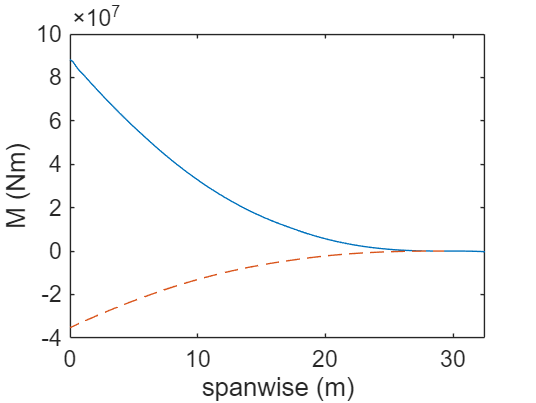

figure(pltidx)
clf;
plot(wing_opt.stripy, M)
hold on
plot(y0, M0,'--')
xlabel("spanwise (m)")
ylabel("M (Nm)")
xlim([0 wing_opt.b/2])

pltidx = pltidx + 1;

Material:

Al7068 =material(); %Aluminum 2024 T861
Al7068.E = 71.2e9; %E - 72-75.7 GPa (@23degC is 73)
Al7068.sigma_y = 648e6; %sigma_y - 400-462 MPa (@23degC is 441)
Al7068.G = 28.5e9; %G - 28-29.4 GPa
Al7068.sigma_y_tensile = 683e6;
Al7068.rho = 2850;
Al7068.price = 3.61;

Al2024 = material();
Al2024.E = 72e9; %E - 72-75.7 GPa (@23degC is 73)
Al2024.sigma_y = 400e6; %sigma_y - 400-462 MPa (@23degC is 441)
Al2024.G = 28e9; %G - 28-29.4 GPa
Al2024.sigma_y_tensile = 441e6;
Al2024.rho = 2780;
Al2024.price = 1.88;

sigma_max = 296e6; %maximum allowable stress

## **WingBox geometry (unchanged throughout)**

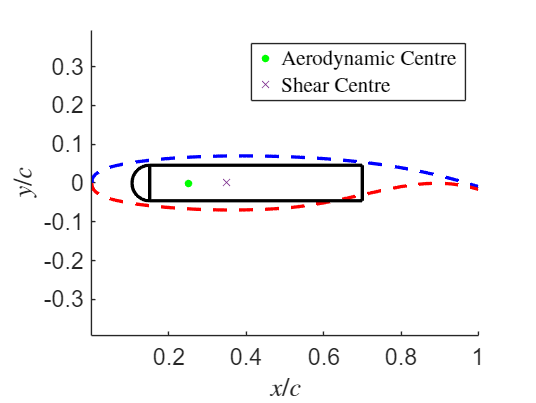

D = 6.38;
wb = wingbox();
%define geometry
wb.b2_c = mean(airfoil.uppershape(:,2) - airfoil.lowershape(:,2));
wb.b_c = 0.15;
wb.c_c = 0.7 - wb.b_c;
%wb = wb.calcR();
wb.R_c = wb.b2_c/2;
%define stringers
wb.L = 1;
%show wingbox:
figure(1)
clf;
wb.drawwithAirfoil(airfoil)
hold on
scatter((wb.b_c + wb.c_c)/2,0,'x')
legend("","","Aerodynamic Centre","","","","","","","","Shear Centre","Interpreter","latex")
xlabel("$x/c$","Interpreter","latex")
ylabel("$y/c$","Interpreter","latex")
print(gcf, fullfile('images_new', 'wingbox.png'), '-dpng', '-r300');

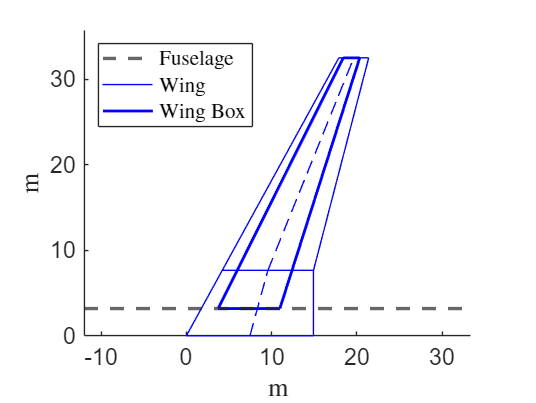


figure(2)
clf;
yline(D/2,'--','LineWidth',2)
hold on
wing_opt.plotWing()
hold on
wb.plotWingBox(wing_opt,D)
axis equal
ylim([0 wing_opt.b/2*1.1])
legend("Fuselage","","","","","","","","","","","","","","","","Wing","","","","","Wing Box","Location","northWest","Interpreter","latex")
xlabel("m","Interpreter","latex")
ylabel("m","Interpreter","latex")
print(gcf, fullfile('images_new', 'wingboxTopView.png'), '-dpng', '-r300');



wb = wb.calcCellArea(wing_opt);
%define rib spacing
wb.a = ones(1,length(wing_opt.stripy)).*5;
wingidx = find(wing_opt.stripy > D/2); % only consider points on the wing
ywing = wing_opt.stripy(wingidx);

Optimizing skins and spars at the same time

-upper skin: easier to buckle in compressive

-lower skin: easier to yield in tension

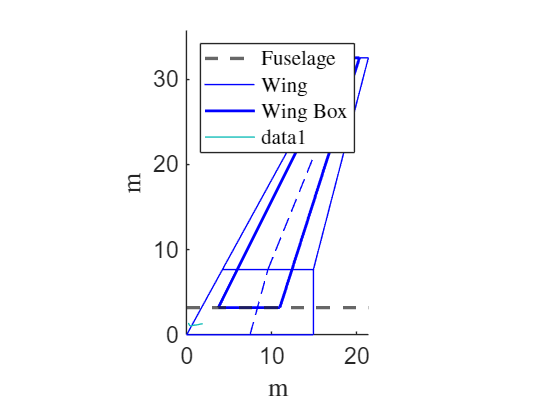

c = wb.c_c .* wing_opt.cn; 
b2 = wb.b2_c .* wing_opt.cn;
N = M ./ c ./ b2;
Nneg = Mneg ./ c ./ b2;

E = Al7068.E;
sigmaY = Al7068.sigma_y;
sigmaYT = Al7068.sigma_y_tensile;

E_L = Al2024.E;
sigmaY_L = Al2024.sigma_y;
sigmaYT_L = Al2024.sigma_y_tensile;

E_r = Al2024.E;
sigmaY_r = Al2024.sigma_y;
sigmaYT_r = Al2024.sigma_y_tensile;

rho_r = Al2024.rho;
rho_Uskin = Al7068.rho;
rho_Lskin = Al2024.rho;
d_hratio = 0.3;

sr_s0_Upper = min(sigmaY./sigma_max,1.4);
[As_bt_vals, ts_t_vals] = findAsbt_ts_for_fb_f0(sr_s0_Upper, 20, 20);

Flist = interpF(As_bt_vals, ts_t_vals);

%crush load
Fcrush = @(M,s,h,t_e,chord,E,I) (M.^2 .* s .* h .* ...
    (t_e) .* chord ./ 2) ./ ...
    (E .* I.^2);

totalM = [];
%loop for each F
wblist = [];
for i = 1:length(Flist)
    if isnan(Flist(i))
        %do nothing
    else
        F = Flist(i);
        As_bt = As_bt_vals(i);
        ts_t = ts_t_vals(i);
        thiswb = wb;
        
        %input upper skin thickness
        t = max(14e-3,N./sigmaY);
        ts = t.*ts_t;
        thiswb.t_Upper = thicknessDoubler(t,wing_opt.stripy,D);
        thiswb.ts_Upper = thicknessDoubler(ts,wing_opt.stripy,D);
        
        %1. upper skin mass
        [thiswb.bs_Upper,thiswb.hs,thiswb.Ks_Upper,thiswb.F,thiswb.sr_s0] = findbs(thiswb.t_Upper, sigmaY, sr_s0_Upper, 3.61, E,As_bt,ts_t,1e-2);
        thiswb.ds = thiswb.hs.*0.3;
        [Mass_Uskin,~,~,thiswb.b1_c] = UskinMass(rho_Uskin, wing_opt, thiswb, wingidx)
        %get rib spacing, becareful with saturation
        thiswb.L = max(N.*E.*(sigmaY./thiswb.F).^(-2), 0.5);
        
        %2. lower skin mass
        %input lower skin thickness
        t_Lower = max(4e-3,N./sigma_max);
        ts_Lower =t_Lower.*ts_t;
        thiswb.t_Lower = thicknessDoubler(t_Lower,wing_opt.stripy,D);
        thiswb.ts_Lower = thicknessDoubler(ts_Lower,wing_opt.stripy,D);
        [thiswb.bs_Lower,thiswb.hs_Lower,thiswb.Ks_Lower,thiswb.F_Lower,thiswb.sr_s0_Lower] = findbs(thiswb.t_Lower, sigmaY_L, sr_s0_Upper, 3.61, E,As_bt,ts_t,1e-2);
        thiswb.ds_Lower = thiswb.hs_Lower.*0.3;
        [Mass_Lskin,~,~,thiswb.b1_c_Lower] = LskinMass(rho_Lskin, wing_opt, thiswb, wingidx)

        %3. rib
        thiswb = thiswb.calcStringerArea();
        thiswb = thiswb.calcStringerArea_Lower();
        h = thiswb.b2_c.*wing_opt.cn;

        t_eff_upper = thiswb.t_Upper + thiswb.As./thiswb.bs_Upper;
        t_eff_upper(isnan(t_eff_upper)) = 0;
        t_eff_lower = thiswb.t_Lower + thiswb.As_Lower./thiswb.bs_Lower;
        t_eff_lower(isnan(t_eff_lower)) = 0;
        chord = wing_opt.cn;
        I_Upper = chord .* (t_eff_upper).^3 ./ 12 + chord .* (t_eff_upper) .* (h./2).^2;
        I_Lower = chord .* (t_eff_lower).^3 ./ 12 + chord .* (t_eff_lower) .* (h./2).^2;

        
        [thiswb.yrib, thiswb.Nrib] = createRibLocationsFromL(thiswb.L, wing_opt, D);
        thiswb = thiswb.mapRibSpacing(wing_opt,D);
        thiswb.L = thiswb.L(152:end);
        thiswb.L = [flip(thiswb.L),NaN,thiswb.L];
        
        %find crush load of all case
        F_pos_upper = abs(Fcrush(M, thiswb.L, h, t_eff_upper, wing_opt.cn, E_r, I_Lower + I_Upper));
        F_neg_upper = abs(Fcrush(Mneg, thiswb.L, h, t_eff_upper, wing_opt.cn, E_r, I_Lower + I_Upper));
        F_pos_lower = abs(Fcrush(M, thiswb.L,h, t_eff_lower, wing_opt.cn, E_r, I_Lower + I_Upper));
        F_neg_lower = abs(Fcrush(Mneg, thiswb.L, h, t_eff_lower, wing_opt.cn, E_r, I_Lower + I_Upper));
        %find the maximum among these
        arrays = {F_pos_upper(wingidx), F_neg_upper(wingidx), F_pos_lower(wingidx), F_neg_lower(wingidx)};
        max_values = cellfun(@(x) max(x(:)), arrays);
        [~, idx] = max(max_values);
        Flarge = arrays{idx};
        
        tr1 = Flarge ./ sigmaY_r ./ wing_opt.cn(wingidx);
        tr2 = (Flarge.*h(wingidx).^2./(3.62.*E_r.*wing_opt.cn(wingidx))).^(1/3);
        tr_max = max(tr1, tr2);
        thiswb.tr = interp1(wing_opt.stripy(wingidx),tr_max,thiswb.yrib(length(thiswb.yrib)/2+1:end));
        thiswb.tr = max(thiswb.tr, 3e-3);
        thiswb.tr = [flip(thiswb.tr); thiswb.tr]
        Mrib = ribMass(thiswb, wing_opt, rho_r)
        
        totalM(i) = Mrib + Mass_Lskin + Mass_Uskin
        wblist = [wblist thiswb];
    end
end

Mass_Uskin = 1.3524e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1154 0.1133 0.1114 0.1095 0.1077 0.1059 0.1042 0.1025 0.1009 0.0993 0.0978 0.0964 0.0949 0.0936 0.0922 0.0909 0.0897 0.0884 0.0872 0.0861 0.0849 0.0838 0.0827 0.0817 0.0807 0.0797 0.0787 0.0777 0.0768 0.0759 0.0750 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.4038 0.4038 0.4038 0.4038 0.4038 0.4038 0.4038 0.4038 0.4038 0.4038 0.4038 0.4038 0.4038 0.4038 0.4038 0.4038 0.4038 0.4038 0.4038 0.4038 0.4038 0.4038 0.4038 0.4038 0.4038 0.4038 0.4038 0.4038 0.4038 0.4038 0.4038 … ] (1×301 double)
       bs_

Mass_Lskin = 1.8289e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1154 0.1133 0.1114 0.1095 0.1077 0.1059 0.1042 0.1025 0.1009 0.0993 0.0978 0.0964 0.0949 0.0936 0.0922 0.0909 0.0897 0.0884 0.0872 0.0861 0.0849 0.0838 0.0827 0.0817 0.0807 0.0797 0.0787 0.0777 0.0768 0.0759 0.0750 … ] (1×301 double)
     b1_c_Lower: [0.0524 0.0515 0.0506 0.0498 0.04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1154 0.1133 0.1114 0.1095 0.1077 0.1059 0.1042 0.1025 0.1009 0.0993 0.0978 0.0964 0.0949 0.0936 0.0922 0.0909 0.0897 0.0884 0.0872 0.0861 0.0849 0.0838 0.0827 0.0817 0.0807 0.0797 0.0787 0.0777 0.0768 0.0759 0.0750 … ] (1×301 double)
     b1_c_Lower: [0.0524 0.0515 0.0506 0.0498 0.04

Mrib = 3.7387e+03

totalM = 1.0e+04 *

         0         0         0         0         0         0    3.5551


Mass_Uskin = 1.4246e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1134 0.1114 0.1095 0.1076 0.1058 0.1041 0.1024 0.1008 0.0992 0.0977 0.0962 0.0947 0.0933 0.0920 0.0907 0.0894 0.0881 0.0869 0.0857 0.0846 0.0835 0.0824 0.0813 0.0803 0.0793 0.0783 0.0774 0.0764 0.0755 0.0746 0.0737 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.3970 0.3970 0.3970 0.3970 0.3970 0.3970 0.3970 0.3970 0.3970 0.3970 0.3970 0.3970 0.3970 0.3970 0.3970 0.3970 0.3970 0.3970 0.3970 0.3970 0.3970 0.3970 0.3970 0.3970 0.3970 0.3970 0.3970 0.3970 0.3970 0.3970 0.3970 … ] (1×301 double)
       bs_

Mass_Lskin = 1.9062e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1134 0.1114 0.1095 0.1076 0.1058 0.1041 0.1024 0.1008 0.0992 0.0977 0.0962 0.0947 0.0933 0.0920 0.0907 0.0894 0.0881 0.0869 0.0857 0.0846 0.0835 0.0824 0.0813 0.0803 0.0793 0.0783 0.0774 0.0764 0.0755 0.0746 0.0737 … ] (1×301 double)
     b1_c_Lower: [0.0516 0.0506 0.0498 0.0489 0.04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1134 0.1114 0.1095 0.1076 0.1058 0.1041 0.1024 0.1008 0.0992 0.0977 0.0962 0.0947 0.0933 0.0920 0.0907 0.0894 0.0881 0.0869 0.0857 0.0846 0.0835 0.0824 0.0813 0.0803 0.0793 0.0783 0.0774 0.0764 0.0755 0.0746 0.0737 … ] (1×301 double)
     b1_c_Lower: [0.0516 0.0506 0.0498 0.0489 0.04

Mrib = 3.7075e+03

totalM = 1.0e+04 *

         0         0         0         0         0         0    3.5551    3.7015


Mass_Uskin = 1.4325e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1121 0.1101 0.1082 0.1063 0.1046 0.1028 0.1012 0.0996 0.0980 0.0965 0.0950 0.0936 0.0922 0.0909 0.0896 0.0883 0.0871 0.0859 0.0847 0.0836 0.0825 0.0814 0.0804 0.0793 0.0783 0.0774 0.0764 0.0755 0.0746 0.0737 0.0729 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.3922 0.3922 0.3922 0.3922 0.3922 0.3922 0.3922 0.3922 0.3922 0.3922 0.3922 0.3922 0.3922 0.3922 0.3922 0.3922 0.3922 0.3922 0.3922 0.3922 0.3922 0.3922 0.3922 0.3922 0.3922 0.3922 0.3922 0.3922 0.3922 0.3922 0.3922 … ] (1×301 double)
       bs_

Mass_Lskin = 1.9320e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1121 0.1101 0.1082 0.1063 0.1046 0.1028 0.1012 0.0996 0.0980 0.0965 0.0950 0.0936 0.0922 0.0909 0.0896 0.0883 0.0871 0.0859 0.0847 0.0836 0.0825 0.0814 0.0804 0.0793 0.0783 0.0774 0.0764 0.0755 0.0746 0.0737 0.0729 … ] (1×301 double)
     b1_c_Lower: [0.0509 0.0500 0.0492 0.0483 0.04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1121 0.1101 0.1082 0.1063 0.1046 0.1028 0.1012 0.0996 0.0980 0.0965 0.0950 0.0936 0.0922 0.0909 0.0896 0.0883 0.0871 0.0859 0.0847 0.0836 0.0825 0.0814 0.0804 0.0793 0.0783 0.0774 0.0764 0.0755 0.0746 0.0737 0.0729 … ] (1×301 double)
     b1_c_Lower: [0.0509 0.0500 0.0492 0.0483 0.04

Mrib = 3.7024e+03

totalM = 1.0e+04 *

         0         0         0         0         0         0    3.5551    3.7015    3.7348


Mass_Uskin = 1.5383e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1109 0.1090 0.1071 0.1053 0.1035 0.1018 0.1002 0.0986 0.0970 0.0955 0.0941 0.0927 0.0913 0.0900 0.0887 0.0874 0.0862 0.0850 0.0839 0.0827 0.0816 0.0806 0.0795 0.0785 0.0776 0.0766 0.0757 0.0747 0.0738 0.0730 0.0721 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 … ] (1×301 double)
       bs_

Mass_Lskin = 2.0728e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1109 0.1090 0.1071 0.1053 0.1035 0.1018 0.1002 0.0986 0.0970 0.0955 0.0941 0.0927 0.0913 0.0900 0.0887 0.0874 0.0862 0.0850 0.0839 0.0827 0.0816 0.0806 0.0795 0.0785 0.0776 0.0766 0.0757 0.0747 0.0738 0.0730 0.0721 … ] (1×301 double)
     b1_c_Lower: [0.0504 0.0495 0.0487 0.0478 0.04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1109 0.1090 0.1071 0.1053 0.1035 0.1018 0.1002 0.0986 0.0970 0.0955 0.0941 0.0927 0.0913 0.0900 0.0887 0.0874 0.0862 0.0850 0.0839 0.0827 0.0816 0.0806 0.0795 0.0785 0.0776 0.0766 0.0757 0.0747 0.0738 0.0730 0.0721 … ] (1×301 double)
     b1_c_Lower: [0.0504 0.0495 0.0487 0.0478 0.04

Mrib = 3.4349e+03

totalM = 1.0e+04 *

         0         0         0         0         0         0    3.5551    3.7015    3.7348    3.9546


Mass_Uskin = 1.6807e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1103 0.1083 0.1064 0.1046 0.1029 0.1012 0.0996 0.0980 0.0964 0.0949 0.0935 0.0921 0.0907 0.0894 0.0881 0.0869 0.0857 0.0845 0.0834 0.0822 0.0812 0.0801 0.0791 0.0781 0.0771 0.0761 0.0752 0.0743 0.0734 0.0725 0.0717 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.3859 0.3859 0.3859 0.3859 0.3859 0.3859 0.3859 0.3859 0.3859 0.3859 0.3859 0.3859 0.3859 0.3859 0.3859 0.3859 0.3859 0.3859 0.3859 0.3859 0.3859 0.3859 0.3859 0.3859 0.3859 0.3859 0.3859 0.3859 0.3859 0.3859 0.3859 … ] (1×301 double)
       bs_

Mass_Lskin = 2.2217e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1103 0.1083 0.1064 0.1046 0.1029 0.1012 0.0996 0.0980 0.0964 0.0949 0.0935 0.0921 0.0907 0.0894 0.0881 0.0869 0.0857 0.0845 0.0834 0.0822 0.0812 0.0801 0.0791 0.0781 0.0771 0.0761 0.0752 0.0743 0.0734 0.0725 0.0717 … ] (1×301 double)
     b1_c_Lower: [0.0501 0.0492 0.0484 0.0476 0.04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1103 0.1083 0.1064 0.1046 0.1029 0.1012 0.0996 0.0980 0.0964 0.0949 0.0935 0.0921 0.0907 0.0894 0.0881 0.0869 0.0857 0.0845 0.0834 0.0822 0.0812 0.0801 0.0791 0.0781 0.0771 0.0761 0.0752 0.0743 0.0734 0.0725 0.0717 … ] (1×301 double)
     b1_c_Lower: [0.0501 0.0492 0.0484 0.0476 0.04

Mrib = 3.2849e+03

totalM = 1.0e+04 *

         0         0         0         0         0         0    3.5551    3.7015    3.7348    3.9546    4.2309


Mass_Uskin = 1.7324e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1101 0.1081 0.1063 0.1045 0.1027 0.1010 0.0994 0.0978 0.0963 0.0948 0.0933 0.0919 0.0906 0.0893 0.0880 0.0867 0.0855 0.0844 0.0832 0.0821 0.0810 0.0800 0.0789 0.0779 0.0770 0.0760 0.0751 0.0742 0.0733 0.0724 0.0716 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 … ] (1×301 double)
       bs_

Mass_Lskin = 2.3046e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1101 0.1081 0.1063 0.1045 0.1027 0.1010 0.0994 0.0978 0.0963 0.0948 0.0933 0.0919 0.0906 0.0893 0.0880 0.0867 0.0855 0.0844 0.0832 0.0821 0.0810 0.0800 0.0789 0.0779 0.0770 0.0760 0.0751 0.0742 0.0733 0.0724 0.0716 … ] (1×301 double)
     b1_c_Lower: [0.0500 0.0492 0.0483 0.0475 0.04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1101 0.1081 0.1063 0.1045 0.1027 0.1010 0.0994 0.0978 0.0963 0.0948 0.0933 0.0919 0.0906 0.0893 0.0880 0.0867 0.0855 0.0844 0.0832 0.0821 0.0810 0.0800 0.0789 0.0779 0.0770 0.0760 0.0751 0.0742 0.0733 0.0724 0.0716 … ] (1×301 double)
     b1_c_Lower: [0.0500 0.0492 0.0483 0.0475 0.04

Mrib = 3.1950e+03

totalM = 1.0e+04 *

         0         0         0         0         0         0    3.5551    3.7015    3.7348    3.9546    4.2309    4.3565


Mass_Uskin = 1.7785e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1100 0.1081 0.1062 0.1044 0.1027 0.1010 0.0994 0.0978 0.0962 0.0948 0.0933 0.0919 0.0906 0.0892 0.0880 0.0867 0.0855 0.0843 0.0832 0.0821 0.0810 0.0799 0.0789 0.0779 0.0769 0.0760 0.0751 0.0741 0.0733 0.0724 0.0716 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.3852 0.3852 0.3852 0.3852 0.3852 0.3852 0.3852 0.3852 0.3852 0.3852 0.3852 0.3852 0.3852 0.3852 0.3852 0.3852 0.3852 0.3852 0.3852 0.3852 0.3852 0.3852 0.3852 0.3852 0.3852 0.3852 0.3852 0.3852 0.3852 0.3852 0.3852 … ] (1×301 double)
       bs_

Mass_Lskin = 2.3641e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1100 0.1081 0.1062 0.1044 0.1027 0.1010 0.0994 0.0978 0.0962 0.0948 0.0933 0.0919 0.0906 0.0892 0.0880 0.0867 0.0855 0.0843 0.0832 0.0821 0.0810 0.0799 0.0789 0.0779 0.0769 0.0760 0.0751 0.0741 0.0733 0.0724 0.0716 … ] (1×301 double)
     b1_c_Lower: [0.0500 0.0491 0.0483 0.0475 0.04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1100 0.1081 0.1062 0.1044 0.1027 0.1010 0.0994 0.0978 0.0962 0.0948 0.0933 0.0919 0.0906 0.0892 0.0880 0.0867 0.0855 0.0843 0.0832 0.0821 0.0810 0.0799 0.0789 0.0779 0.0769 0.0760 0.0751 0.0741 0.0733 0.0724 0.0716 … ] (1×301 double)
     b1_c_Lower: [0.0500 0.0491 0.0483 0.0475 0.04

Mrib = 3.1102e+03

totalM = 1.0e+04 *

         0         0         0         0         0         0    3.5551    3.7015    3.7348    3.9546    4.2309    4.3565    4.4536


Mass_Uskin = 1.8689e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1101 0.1081 0.1063 0.1045 0.1027 0.1010 0.0994 0.0978 0.0963 0.0948 0.0933 0.0919 0.0906 0.0893 0.0880 0.0867 0.0855 0.0844 0.0832 0.0821 0.0810 0.0800 0.0789 0.0779 0.0770 0.0760 0.0751 0.0742 0.0733 0.0724 0.0716 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 … ] (1×301 double)
       bs_

Mass_Lskin = 2.5011e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1101 0.1081 0.1063 0.1045 0.1027 0.1010 0.0994 0.0978 0.0963 0.0948 0.0933 0.0919 0.0906 0.0893 0.0880 0.0867 0.0855 0.0844 0.0832 0.0821 0.0810 0.0800 0.0789 0.0779 0.0770 0.0760 0.0751 0.0742 0.0733 0.0724 0.0716 … ] (1×301 double)
     b1_c_Lower: [0.0500 0.0492 0.0483 0.0475 0.04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1101 0.1081 0.1063 0.1045 0.1027 0.1010 0.0994 0.0978 0.0963 0.0948 0.0933 0.0919 0.0906 0.0893 0.0880 0.0867 0.0855 0.0844 0.0832 0.0821 0.0810 0.0800 0.0789 0.0779 0.0770 0.0760 0.0751 0.0742 0.0733 0.0724 0.0716 … ] (1×301 double)
     b1_c_Lower: [0.0500 0.0492 0.0483 0.0475 0.04

Mrib = 2.9948e+03

totalM = 1.0e+04 *

         0         0         0         0         0         0    3.5551    3.7015    3.7348    3.9546    4.2309    4.3565    4.4536    4.6695


Mass_Uskin = 1.9430e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1100 0.1080 0.1061 0.1043 0.1026 0.1009 0.0993 0.0977 0.0962 0.0947 0.0932 0.0918 0.0905 0.0892 0.0879 0.0867 0.0854 0.0843 0.0831 0.0820 0.0809 0.0799 0.0789 0.0779 0.0769 0.0759 0.0750 0.0741 0.0732 0.0723 0.0715 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.3848 0.3848 0.3848 0.3848 0.3848 0.3848 0.3848 0.3848 0.3848 0.3848 0.3848 0.3848 0.3848 0.3848 0.3848 0.3848 0.3848 0.3848 0.3848 0.3848 0.3848 0.3848 0.3848 0.3848 0.3848 0.3848 0.3848 0.3848 0.3848 0.3848 0.3848 … ] (1×301 double)
       bs_

Mass_Lskin = 2.6208e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1100 0.1080 0.1061 0.1043 0.1026 0.1009 0.0993 0.0977 0.0962 0.0947 0.0932 0.0918 0.0905 0.0892 0.0879 0.0867 0.0854 0.0843 0.0831 0.0820 0.0809 0.0799 0.0789 0.0779 0.0769 0.0759 0.0750 0.0741 0.0732 0.0723 0.0715 … ] (1×301 double)
     b1_c_Lower: [0.0500 0.0491 0.0483 0.0474 0.04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1100 0.1080 0.1061 0.1043 0.1026 0.1009 0.0993 0.0977 0.0962 0.0947 0.0932 0.0918 0.0905 0.0892 0.0879 0.0867 0.0854 0.0843 0.0831 0.0820 0.0809 0.0799 0.0789 0.0779 0.0769 0.0759 0.0750 0.0741 0.0732 0.0723 0.0715 … ] (1×301 double)
     b1_c_Lower: [0.0500 0.0491 0.0483 0.0474 0.04

Mrib = 2.9111e+03

totalM = 1.0e+04 *

         0         0         0         0         0         0    3.5551    3.7015    3.7348    3.9546    4.2309    4.3565    4.4536    4.6695    4.8550


Mass_Uskin = 1.9583e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1100 0.1080 0.1062 0.1044 0.1026 0.1009 0.0993 0.0977 0.0962 0.0947 0.0932 0.0919 0.0905 0.0892 0.0879 0.0867 0.0855 0.0843 0.0831 0.0820 0.0809 0.0799 0.0789 0.0779 0.0769 0.0759 0.0750 0.0741 0.0732 0.0723 0.0715 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.3849 0.3849 0.3849 0.3849 0.3849 0.3849 0.3849 0.3849 0.3849 0.3849 0.3849 0.3849 0.3849 0.3849 0.3849 0.3849 0.3849 0.3849 0.3849 0.3849 0.3849 0.3849 0.3849 0.3849 0.3849 0.3849 0.3849 0.3849 0.3849 0.3849 0.3849 … ] (1×301 double)
       bs_

Mass_Lskin = 2.6413e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1100 0.1080 0.1062 0.1044 0.1026 0.1009 0.0993 0.0977 0.0962 0.0947 0.0932 0.0919 0.0905 0.0892 0.0879 0.0867 0.0855 0.0843 0.0831 0.0820 0.0809 0.0799 0.0789 0.0779 0.0769 0.0759 0.0750 0.0741 0.0732 0.0723 0.0715 … ] (1×301 double)
     b1_c_Lower: [0.0500 0.0491 0.0483 0.0474 0.04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1100 0.1080 0.1062 0.1044 0.1026 0.1009 0.0993 0.0977 0.0962 0.0947 0.0932 0.0919 0.0905 0.0892 0.0879 0.0867 0.0855 0.0843 0.0831 0.0820 0.0809 0.0799 0.0789 0.0779 0.0769 0.0759 0.0750 0.0741 0.0732 0.0723 0.0715 … ] (1×301 double)
     b1_c_Lower: [0.0500 0.0491 0.0483 0.0474 0.04

Mrib = 2.9022e+03

totalM = 1.0e+04 *

         0         0         0         0         0         0    3.5551    3.7015    3.7348    3.9546    4.2309    4.3565    4.4536    4.6695    4.8550    4.8898


Mass_Uskin = 2.1200e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1099 0.1080 0.1061 0.1043 0.1025 0.1008 0.0992 0.0976 0.0961 0.0946 0.0932 0.0918 0.0904 0.0891 0.0878 0.0866 0.0854 0.0842 0.0831 0.0820 0.0809 0.0798 0.0788 0.0778 0.0768 0.0759 0.0749 0.0740 0.0732 0.0723 0.0715 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.3846 0.3846 0.3846 0.3846 0.3846 0.3846 0.3846 0.3846 0.3846 0.3846 0.3846 0.3846 0.3846 0.3846 0.3846 0.3846 0.3846 0.3846 0.3846 0.3846 0.3846 0.3846 0.3846 0.3846 0.3846 0.3846 0.3846 0.3846 0.3846 0.3846 0.3846 … ] (1×301 double)
       bs_

Mass_Lskin = 2.7942e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1099 0.1080 0.1061 0.1043 0.1025 0.1008 0.0992 0.0976 0.0961 0.0946 0.0932 0.0918 0.0904 0.0891 0.0878 0.0866 0.0854 0.0842 0.0831 0.0820 0.0809 0.0798 0.0788 0.0778 0.0768 0.0759 0.0749 0.0740 0.0732 0.0723 0.0715 … ] (1×301 double)
     b1_c_Lower: [0.0500 0.0491 0.0482 0.0474 0.04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1099 0.1080 0.1061 0.1043 0.1025 0.1008 0.0992 0.0976 0.0961 0.0946 0.0932 0.0918 0.0904 0.0891 0.0878 0.0866 0.0854 0.0842 0.0831 0.0820 0.0809 0.0798 0.0788 0.0778 0.0768 0.0759 0.0749 0.0740 0.0732 0.0723 0.0715 … ] (1×301 double)
     b1_c_Lower: [0.0500 0.0491 0.0482 0.0474 0.04

Mrib = 2.8012e+03

totalM = 1.0e+04 *

         0         0         0         0         0         0    3.5551    3.7015    3.7348    3.9546    4.2309    4.3565    4.4536    4.6695    4.8550    4.8898    5.1943


Mass_Uskin = 2.2122e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1101 0.1082 0.1063 0.1045 0.1028 0.1011 0.0994 0.0978 0.0963 0.0948 0.0934 0.0920 0.0906 0.0893 0.0880 0.0868 0.0856 0.0844 0.0833 0.0821 0.0811 0.0800 0.0790 0.0780 0.0770 0.0760 0.0751 0.0742 0.0733 0.0724 0.0716 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.3854 0.3854 0.3854 0.3854 0.3854 0.3854 0.3854 0.3854 0.3854 0.3854 0.3854 0.3854 0.3854 0.3854 0.3854 0.3854 0.3854 0.3854 0.3854 0.3854 0.3854 0.3854 0.3854 0.3854 0.3854 0.3854 0.3854 0.3854 0.3854 0.3854 0.3854 … ] (1×301 double)
       bs_

Mass_Lskin = 2.9126e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1101 0.1082 0.1063 0.1045 0.1028 0.1011 0.0994 0.0978 0.0963 0.0948 0.0934 0.0920 0.0906 0.0893 0.0880 0.0868 0.0856 0.0844 0.0833 0.0821 0.0811 0.0800 0.0790 0.0780 0.0770 0.0760 0.0751 0.0742 0.0733 0.0724 0.0716 … ] (1×301 double)
     b1_c_Lower: [0.0501 0.0492 0.0483 0.0475 0.04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1101 0.1082 0.1063 0.1045 0.1028 0.1011 0.0994 0.0978 0.0963 0.0948 0.0934 0.0920 0.0906 0.0893 0.0880 0.0868 0.0856 0.0844 0.0833 0.0821 0.0811 0.0800 0.0790 0.0780 0.0770 0.0760 0.0751 0.0742 0.0733 0.0724 0.0716 … ] (1×301 double)
     b1_c_Lower: [0.0501 0.0492 0.0483 0.0475 0.04

Mrib = 2.7677e+03

totalM = 1.0e+04 *

         0         0         0         0         0         0    3.5551    3.7015    3.7348    3.9546    4.2309    4.3565    4.4536    4.6695    4.8550    4.8898    5.1943    5.4016


Mass_Uskin = 2.3072e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1101 0.1081 0.1063 0.1045 0.1027 0.1010 0.0994 0.0978 0.0963 0.0948 0.0933 0.0919 0.0906 0.0893 0.0880 0.0867 0.0855 0.0844 0.0832 0.0821 0.0810 0.0800 0.0789 0.0779 0.0770 0.0760 0.0751 0.0742 0.0733 0.0724 0.0716 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 … ] (1×301 double)
       bs_

Mass_Lskin = 3.0915e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1101 0.1081 0.1063 0.1045 0.1027 0.1010 0.0994 0.0978 0.0963 0.0948 0.0933 0.0919 0.0906 0.0893 0.0880 0.0867 0.0855 0.0844 0.0832 0.0821 0.0810 0.0800 0.0789 0.0779 0.0770 0.0760 0.0751 0.0742 0.0733 0.0724 0.0716 … ] (1×301 double)
     b1_c_Lower: [0.0500 0.0492 0.0483 0.0475 0.04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1101 0.1081 0.1063 0.1045 0.1027 0.1010 0.0994 0.0978 0.0963 0.0948 0.0933 0.0919 0.0906 0.0893 0.0880 0.0867 0.0855 0.0844 0.0832 0.0821 0.0810 0.0800 0.0789 0.0779 0.0770 0.0760 0.0751 0.0742 0.0733 0.0724 0.0716 … ] (1×301 double)
     b1_c_Lower: [0.0500 0.0492 0.0483 0.0475 0.04

Mrib = 2.6862e+03

totalM = 1.0e+04 *

         0         0         0         0         0         0    3.5551    3.7015    3.7348    3.9546    4.2309    4.3565    4.4536    4.6695    4.8550    4.8898    5.1943    5.4016    5.6674


Mass_Uskin = 2.3620e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1101 0.1081 0.1063 0.1045 0.1027 0.1010 0.0994 0.0978 0.0963 0.0948 0.0933 0.0919 0.0906 0.0893 0.0880 0.0868 0.0855 0.0844 0.0832 0.0821 0.0810 0.0800 0.0789 0.0779 0.0770 0.0760 0.0751 0.0742 0.0733 0.0724 0.0716 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 0.3853 … ] (1×301 double)
       bs_

Mass_Lskin = 3.1642e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1101 0.1081 0.1063 0.1045 0.1027 0.1010 0.0994 0.0978 0.0963 0.0948 0.0933 0.0919 0.0906 0.0893 0.0880 0.0868 0.0855 0.0844 0.0832 0.0821 0.0810 0.0800 0.0789 0.0779 0.0770 0.0760 0.0751 0.0742 0.0733 0.0724 0.0716 … ] (1×301 double)
     b1_c_Lower: [0.0500 0.0492 0.0483 0.0475 0.04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1101 0.1081 0.1063 0.1045 0.1027 0.1010 0.0994 0.0978 0.0963 0.0948 0.0933 0.0919 0.0906 0.0893 0.0880 0.0868 0.0855 0.0844 0.0832 0.0821 0.0810 0.0800 0.0789 0.0779 0.0770 0.0760 0.0751 0.0742 0.0733 0.0724 0.0716 … ] (1×301 double)
     b1_c_Lower: [0.0500 0.0492 0.0483 0.0475 0.04

Mrib = 2.6688e+03

totalM = 1.0e+04 *

         0         0         0         0         0         0    3.5551    3.7015    3.7348    3.9546    4.2309    4.3565    4.4536    4.6695    4.8550    4.8898    5.1943    5.4016    5.6674    5.7931


Mass_Uskin = 2.3960e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1104 0.1084 0.1065 0.1047 0.1030 0.1013 0.0996 0.0980 0.0965 0.0950 0.0936 0.0922 0.0908 0.0895 0.0882 0.0870 0.0858 0.0846 0.0834 0.0823 0.0812 0.0802 0.0791 0.0781 0.0772 0.0762 0.0753 0.0744 0.0735 0.0726 0.0718 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.3862 0.3862 0.3862 0.3862 0.3862 0.3862 0.3862 0.3862 0.3862 0.3862 0.3862 0.3862 0.3862 0.3862 0.3862 0.3862 0.3862 0.3862 0.3862 0.3862 0.3862 0.3862 0.3862 0.3862 0.3862 0.3862 0.3862 0.3862 0.3862 0.3862 0.3862 … ] (1×301 double)
       bs_

Mass_Lskin = 3.2094e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1104 0.1084 0.1065 0.1047 0.1030 0.1013 0.0996 0.0980 0.0965 0.0950 0.0936 0.0922 0.0908 0.0895 0.0882 0.0870 0.0858 0.0846 0.0834 0.0823 0.0812 0.0802 0.0791 0.0781 0.0772 0.0762 0.0753 0.0744 0.0735 0.0726 0.0718 … ] (1×301 double)
     b1_c_Lower: [0.0502 0.0493 0.0484 0.0476 0.04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1104 0.1084 0.1065 0.1047 0.1030 0.1013 0.0996 0.0980 0.0965 0.0950 0.0936 0.0922 0.0908 0.0895 0.0882 0.0870 0.0858 0.0846 0.0834 0.0823 0.0812 0.0802 0.0791 0.0781 0.0772 0.0762 0.0753 0.0744 0.0735 0.0726 0.0718 … ] (1×301 double)
     b1_c_Lower: [0.0502 0.0493 0.0484 0.0476 0.04

Mrib = 2.6573e+03

totalM = 1.0e+04 *

         0         0         0         0         0         0    3.5551    3.7015    3.7348    3.9546    4.2309    4.3565    4.4536    4.6695    4.8550    4.8898    5.1943    5.4016    5.6674    5.7931    5.8711


Mass_Uskin = 2.5573e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1108 0.1089 0.1070 0.1052 0.1034 0.1017 0.1001 0.0985 0.0969 0.0954 0.0940 0.0926 0.0912 0.0899 0.0886 0.0873 0.0861 0.0849 0.0838 0.0827 0.0816 0.0805 0.0795 0.0785 0.0775 0.0765 0.0756 0.0747 0.0738 0.0729 0.0721 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.3879 0.3879 0.3879 0.3879 0.3879 0.3879 0.3879 0.3879 0.3879 0.3879 0.3879 0.3879 0.3879 0.3879 0.3879 0.3879 0.3879 0.3879 0.3879 0.3879 0.3879 0.3879 0.3879 0.3879 0.3879 0.3879 0.3879 0.3879 0.3879 0.3879 0.3879 … ] (1×301 double)
       bs_

Mass_Lskin = 3.3605e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1108 0.1089 0.1070 0.1052 0.1034 0.1017 0.1001 0.0985 0.0969 0.0954 0.0940 0.0926 0.0912 0.0899 0.0886 0.0873 0.0861 0.0849 0.0838 0.0827 0.0816 0.0805 0.0795 0.0785 0.0775 0.0765 0.0756 0.0747 0.0738 0.0729 0.0721 … ] (1×301 double)
     b1_c_Lower: [0.0504 0.0495 0.0486 0.0478 0.04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1108 0.1089 0.1070 0.1052 0.1034 0.1017 0.1001 0.0985 0.0969 0.0954 0.0940 0.0926 0.0912 0.0899 0.0886 0.0873 0.0861 0.0849 0.0838 0.0827 0.0816 0.0805 0.0795 0.0785 0.0775 0.0765 0.0756 0.0747 0.0738 0.0729 0.0721 … ] (1×301 double)
     b1_c_Lower: [0.0504 0.0495 0.0486 0.0478 0.04

Mrib = 2.5856e+03

totalM = 1.0e+04 *

         0         0         0         0         0         0    3.5551    3.7015    3.7348    3.9546    4.2309    4.3565    4.4536    4.6695    4.8550    4.8898    5.1943    5.4016    5.6674    5.7931    5.8711    6.1764


Mass_Uskin = 2.6393e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1109 0.1089 0.1070 0.1052 0.1035 0.1018 0.1001 0.0985 0.0970 0.0955 0.0940 0.0926 0.0913 0.0899 0.0886 0.0874 0.0862 0.0850 0.0838 0.0827 0.0816 0.0806 0.0795 0.0785 0.0775 0.0766 0.0756 0.0747 0.0738 0.0730 0.0721 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.3881 0.3881 0.3881 0.3881 0.3881 0.3881 0.3881 0.3881 0.3881 0.3881 0.3881 0.3881 0.3881 0.3881 0.3881 0.3881 0.3881 0.3881 0.3881 0.3881 0.3881 0.3881 0.3881 0.3881 0.3881 0.3881 0.3881 0.3881 0.3881 0.3881 0.3881 … ] (1×301 double)
       bs_

Mass_Lskin = 3.5003e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1109 0.1089 0.1070 0.1052 0.1035 0.1018 0.1001 0.0985 0.0970 0.0955 0.0940 0.0926 0.0913 0.0899 0.0886 0.0874 0.0862 0.0850 0.0838 0.0827 0.0816 0.0806 0.0795 0.0785 0.0775 0.0766 0.0756 0.0747 0.0738 0.0730 0.0721 … ] (1×301 double)
     b1_c_Lower: [0.0504 0.0495 0.0487 0.0478 0.04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1109 0.1089 0.1070 0.1052 0.1035 0.1018 0.1001 0.0985 0.0970 0.0955 0.0940 0.0926 0.0913 0.0899 0.0886 0.0874 0.0862 0.0850 0.0838 0.0827 0.0816 0.0806 0.0795 0.0785 0.0775 0.0766 0.0756 0.0747 0.0738 0.0730 0.0721 … ] (1×301 double)
     b1_c_Lower: [0.0504 0.0495 0.0487 0.0478 0.04

Mrib = 2.5645e+03

totalM = 1.0e+04 *

         0         0         0         0         0         0    3.5551    3.7015    3.7348    3.9546    4.2309    4.3565    4.4536    4.6695    4.8550    4.8898    5.1943    5.4016    5.6674    5.7931    5.8711    6.1764    6.3961


Mass_Uskin = 2.6428e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1109 0.1090 0.1071 0.1052 0.1035 0.1018 0.1001 0.0985 0.0970 0.0955 0.0940 0.0926 0.0913 0.0899 0.0887 0.0874 0.0862 0.0850 0.0838 0.0827 0.0816 0.0806 0.0795 0.0785 0.0775 0.0766 0.0756 0.0747 0.0738 0.0730 0.0721 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 0.3882 … ] (1×301 double)
       bs_

Mass_Lskin = 3.5049e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1109 0.1090 0.1071 0.1052 0.1035 0.1018 0.1001 0.0985 0.0970 0.0955 0.0940 0.0926 0.0913 0.0899 0.0887 0.0874 0.0862 0.0850 0.0838 0.0827 0.0816 0.0806 0.0795 0.0785 0.0775 0.0766 0.0756 0.0747 0.0738 0.0730 0.0721 … ] (1×301 double)
     b1_c_Lower: [0.0504 0.0495 0.0487 0.0478 0.04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1109 0.1090 0.1071 0.1052 0.1035 0.1018 0.1001 0.0985 0.0970 0.0955 0.0940 0.0926 0.0913 0.0899 0.0887 0.0874 0.0862 0.0850 0.0838 0.0827 0.0816 0.0806 0.0795 0.0785 0.0775 0.0766 0.0756 0.0747 0.0738 0.0730 0.0721 … ] (1×301 double)
     b1_c_Lower: [0.0504 0.0495 0.0487 0.0478 0.04

Mrib = 2.5642e+03

totalM = 1.0e+04 *

         0         0         0         0         0         0    3.5551    3.7015    3.7348    3.9546    4.2309    4.3565    4.4536    4.6695    4.8550    4.8898    5.1943    5.4016    5.6674    5.7931    5.8711    6.1764    6.3961    6.4041


Mass_Uskin = 2.7234e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1108 0.1089 0.1070 0.1052 0.1034 0.1017 0.1000 0.0985 0.0969 0.0954 0.0940 0.0926 0.0912 0.0899 0.0886 0.0873 0.0861 0.0849 0.0838 0.0827 0.0816 0.0805 0.0795 0.0785 0.0775 0.0765 0.0756 0.0747 0.0738 0.0729 0.0721 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.3878 0.3878 0.3878 0.3878 0.3878 0.3878 0.3878 0.3878 0.3878 0.3878 0.3878 0.3878 0.3878 0.3878 0.3878 0.3878 0.3878 0.3878 0.3878 0.3878 0.3878 0.3878 0.3878 0.3878 0.3878 0.3878 0.3878 0.3878 0.3878 0.3878 0.3878 … ] (1×301 double)
       bs_

Mass_Lskin = 3.6453e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1108 0.1089 0.1070 0.1052 0.1034 0.1017 0.1000 0.0985 0.0969 0.0954 0.0940 0.0926 0.0912 0.0899 0.0886 0.0873 0.0861 0.0849 0.0838 0.0827 0.0816 0.0805 0.0795 0.0785 0.0775 0.0765 0.0756 0.0747 0.0738 0.0729 0.0721 … ] (1×301 double)
     b1_c_Lower: [0.0504 0.0495 0.0486 0.0478 0.04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1108 0.1089 0.1070 0.1052 0.1034 0.1017 0.1000 0.0985 0.0969 0.0954 0.0940 0.0926 0.0912 0.0899 0.0886 0.0873 0.0861 0.0849 0.0838 0.0827 0.0816 0.0805 0.0795 0.0785 0.0775 0.0765 0.0756 0.0747 0.0738 0.0729 0.0721 … ] (1×301 double)
     b1_c_Lower: [0.0504 0.0495 0.0486 0.0478 0.04

Mrib = 2.5482e+03

totalM = 1.0e+04 *

         0         0         0         0         0         0    3.5551    3.7015    3.7348    3.9546    4.2309    4.3565    4.4536    4.6695    4.8550    4.8898    5.1943    5.4016    5.6674    5.7931    5.8711    6.1764    6.3961    6.4041    6.6235


Mass_Uskin = 2.8052e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1106 0.1086 0.1067 0.1049 0.1032 0.1015 0.0998 0.0982 0.0967 0.0952 0.0937 0.0923 0.0910 0.0897 0.0884 0.0871 0.0859 0.0847 0.0836 0.0825 0.0814 0.0803 0.0793 0.0783 0.0773 0.0763 0.0754 0.0745 0.0736 0.0727 0.0719 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.3869 0.3869 0.3869 0.3869 0.3869 0.3869 0.3869 0.3869 0.3869 0.3869 0.3869 0.3869 0.3869 0.3869 0.3869 0.3869 0.3869 0.3869 0.3869 0.3869 0.3869 0.3869 0.3869 0.3869 0.3869 0.3869 0.3869 0.3869 0.3869 0.3869 0.3869 … ] (1×301 double)
       bs_

Mass_Lskin = 3.7918e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1106 0.1086 0.1067 0.1049 0.1032 0.1015 0.0998 0.0982 0.0967 0.0952 0.0937 0.0923 0.0910 0.0897 0.0884 0.0871 0.0859 0.0847 0.0836 0.0825 0.0814 0.0803 0.0793 0.0783 0.0773 0.0763 0.0754 0.0745 0.0736 0.0727 0.0719 … ] (1×301 double)
     b1_c_Lower: [0.0503 0.0494 0.0485 0.0477 0.04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1106 0.1086 0.1067 0.1049 0.1032 0.1015 0.0998 0.0982 0.0967 0.0952 0.0937 0.0923 0.0910 0.0897 0.0884 0.0871 0.0859 0.0847 0.0836 0.0825 0.0814 0.0803 0.0793 0.0783 0.0773 0.0763 0.0754 0.0745 0.0736 0.0727 0.0719 … ] (1×301 double)
     b1_c_Lower: [0.0503 0.0494 0.0485 0.0477 0.04

Mrib = 2.5464e+03

totalM = 1.0e+04 *

         0         0         0         0         0         0    3.5551    3.7015    3.7348    3.9546    4.2309    4.3565    4.4536    4.6695    4.8550    4.8898    5.1943    5.4016    5.6674    5.7931    5.8711    6.1764    6.3961    6.4041    6.6235    6.8517


Mass_Uskin = 2.9227e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1108 0.1088 0.1069 0.1051 0.1033 0.1016 0.1000 0.0984 0.0969 0.0954 0.0939 0.0925 0.0911 0.0898 0.0885 0.0873 0.0861 0.0849 0.0837 0.0826 0.0815 0.0805 0.0794 0.0784 0.0774 0.0765 0.0755 0.0746 0.0737 0.0729 0.0720 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.3876 0.3876 0.3876 0.3876 0.3876 0.3876 0.3876 0.3876 0.3876 0.3876 0.3876 0.3876 0.3876 0.3876 0.3876 0.3876 0.3876 0.3876 0.3876 0.3876 0.3876 0.3876 0.3876 0.3876 0.3876 0.3876 0.3876 0.3876 0.3876 0.3876 0.3876 … ] (1×301 double)
       bs_

Mass_Lskin = 3.8512e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1108 0.1088 0.1069 0.1051 0.1033 0.1016 0.1000 0.0984 0.0969 0.0954 0.0939 0.0925 0.0911 0.0898 0.0885 0.0873 0.0861 0.0849 0.0837 0.0826 0.0815 0.0805 0.0794 0.0784 0.0774 0.0765 0.0755 0.0746 0.0737 0.0729 0.0720 … ] (1×301 double)
     b1_c_Lower: [0.0503 0.0495 0.0486 0.0478 0.04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1108 0.1088 0.1069 0.1051 0.1033 0.1016 0.1000 0.0984 0.0969 0.0954 0.0939 0.0925 0.0911 0.0898 0.0885 0.0873 0.0861 0.0849 0.0837 0.0826 0.0815 0.0805 0.0794 0.0784 0.0774 0.0765 0.0755 0.0746 0.0737 0.0729 0.0720 … ] (1×301 double)
     b1_c_Lower: [0.0503 0.0495 0.0486 0.0478 0.04

Mrib = 2.5381e+03

totalM = 1.0e+04 *

         0         0         0         0         0         0    3.5551    3.7015    3.7348    3.9546    4.2309    4.3565    4.4536    4.6695    4.8550    4.8898    5.1943    5.4016    5.6674    5.7931    5.8711    6.1764    6.3961    6.4041    6.6235    6.8517    7.0277


Mass_Uskin = 2.9626e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1108 0.1088 0.1069 0.1051 0.1033 0.1016 0.1000 0.0984 0.0969 0.0954 0.0939 0.0925 0.0911 0.0898 0.0885 0.0873 0.0861 0.0849 0.0837 0.0826 0.0815 0.0805 0.0794 0.0784 0.0774 0.0765 0.0755 0.0746 0.0737 0.0729 0.0720 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.3877 0.3877 0.3877 0.3877 0.3877 0.3877 0.3877 0.3877 0.3877 0.3877 0.3877 0.3877 0.3877 0.3877 0.3877 0.3877 0.3877 0.3877 0.3877 0.3877 0.3877 0.3877 0.3877 0.3877 0.3877 0.3877 0.3877 0.3877 0.3877 0.3877 0.3877 … ] (1×301 double)
       bs_

Mass_Lskin = 3.9029e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1108 0.1088 0.1069 0.1051 0.1033 0.1016 0.1000 0.0984 0.0969 0.0954 0.0939 0.0925 0.0911 0.0898 0.0885 0.0873 0.0861 0.0849 0.0837 0.0826 0.0815 0.0805 0.0794 0.0784 0.0774 0.0765 0.0755 0.0746 0.0737 0.0729 0.0720 … ] (1×301 double)
     b1_c_Lower: [0.0503 0.0495 0.0486 0.0478 0.04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1108 0.1088 0.1069 0.1051 0.1033 0.1016 0.1000 0.0984 0.0969 0.0954 0.0939 0.0925 0.0911 0.0898 0.0885 0.0873 0.0861 0.0849 0.0837 0.0826 0.0815 0.0805 0.0794 0.0784 0.0774 0.0765 0.0755 0.0746 0.0737 0.0729 0.0720 … ] (1×301 double)
     b1_c_Lower: [0.0503 0.0495 0.0486 0.0478 0.04

Mrib = 2.5340e+03

totalM = 1.0e+04 *

         0         0         0         0         0         0    3.5551    3.7015    3.7348    3.9546    4.2309    4.3565    4.4536    4.6695    4.8550    4.8898    5.1943    5.4016    5.6674    5.7931    5.8711    6.1764    6.3961    6.4041    6.6235    6.8517    7.0277    7.1189


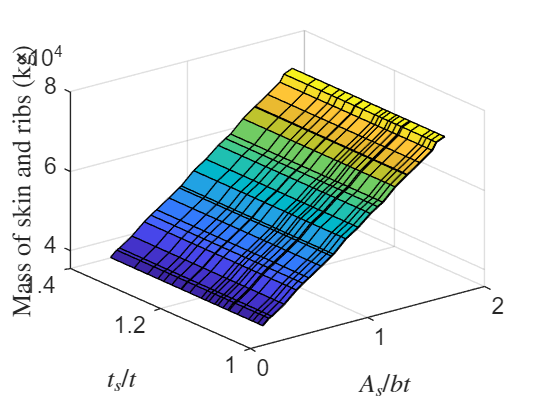

totalM(totalM == 0) = NaN;
[~,minidx] = min(totalM);
%minidx = length(wblist);
wb = wblist(minidx);
As_bt = As_bt_vals(minidx);
ts_t = ts_t_vals(minidx);


[X, Y] = meshgrid(As_bt_vals, ts_t_vals);
Z = repmat(totalM, length(ts_t_vals), 1);  % Replicate totalM along each row
figure(2);
clf;
surf(X, Y, Z);
xlabel('$A_s/bt$',"Interpreter","latex");
ylabel('$t_s/t$',"Interpreter","latex");
zlabel("Mass of skin and ribs (kg)","Interpreter","latex")
print(gcf, fullfile('images_new', 'Optimization.png'), '-dpng', '-r300')

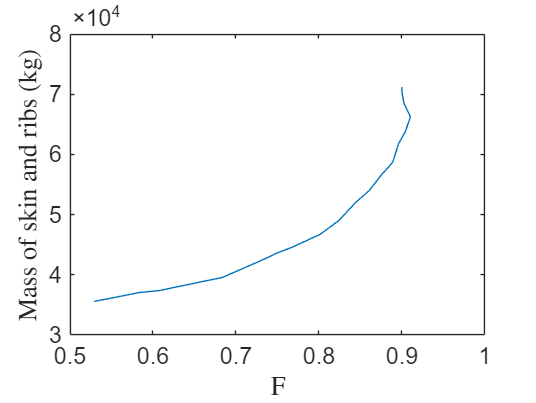


figure(3)
clf;
plot(Flist,totalM)
xlabel("F","Interpreter","latex")
ylabel("Mass of skin and ribs (kg)","Interpreter","latex")
print(gcf, fullfile('images_new', 'MvsF.png'), '-dpng', '-r300')



figure(5)
clf;
% Global Buckling: Solid Blue, Thick
sigmaGlobal =  wb.sr_s0.*wb.Ks_Upper.*E.*(wb.t_Upper./(wb.b1_c.*wing_opt.cn)).^2;
plot(wing_opt.stripy(wingidx), sigmaGlobal(wingidx)*1e-6, ...
    'LineStyle', '--', 'Color', [0, 0.4470, 0.7410], 'LineWidth', 2);
hold on;
% Local Buckling: Dashed Orange, Medium
sigmaLocal = wb.F.* sqrt(N.*E./wb.L);
sigmacr_Uskin = sigmaLocal;
plot(wing_opt.stripy(wingidx), sigmaLocal(wingidx).*1e-6, ...
    'LineStyle', '-', 'Color', [0.8500, 0.3250, 0.0980], 'LineWidth', 1.5);

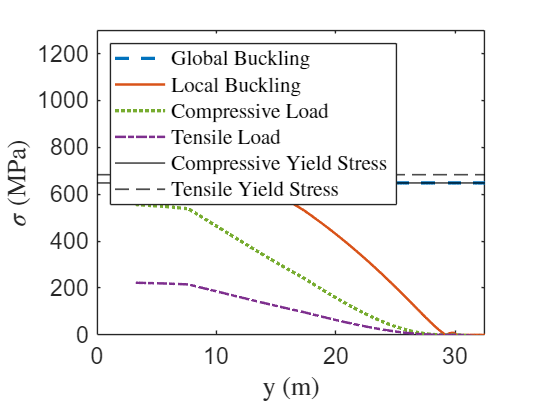

% Compressive Load: Dotted Green, Thick
plot(wing_opt.stripy(wingidx), N(wingidx)./wb.t_Upper(wingidx)*1e-6, ...
    'LineStyle', ':', 'Color', [0.4660, 0.6740, 0.1880], 'LineWidth', 2);
sigma_Uskin = N./wb.t_Upper;
% Tensile Load: Dash-Dot Purple, Medium
plot(wing_opt.stripy(wingidx), -Nneg(wingidx)./wb.t_Upper(wingidx)*1e-6, ...
    'LineStyle', '-.', 'Color', [0.4940, 0.1840, 0.5560], 'LineWidth', 1.5);
% Compressive Yield: Solid Black
yline(sigmaY*1e-6, 'LineStyle', '-', 'Color', 'k', 'LineWidth', 1);
% Tensile Yield: Dashed Black
yline(sigmaYT*1e-6, 'LineStyle', '--', 'Color', 'k', 'LineWidth', 1);

legend("Global Buckling","Local Buckling","Compressive Load","Tensile Load",...
    "Compressive Yield Stress","Tensile Yield Stress", "Interpreter","latex","Location","northwest");
xlabel("y (m)", "Interpreter", "latex");
ylabel("$\sigma$ (MPa)", "Interpreter", "latex");
xlim([0 wing_opt.s]);
ylim([0 1300])
print(gcf, fullfile('images_new', 'UpperStressDiagram.png'), '-dpng', '-r300')



figure(7)
clf;
% Global Buckling: Solid Blue, Thick
sigmaGlobal =  wb.sr_s0_Lower.*wb.Ks_Lower.*E.*(wb.t_Lower./(wb.b1_c_Lower.*wing_opt.cn)).^2;
plot(wing_opt.stripy(wingidx), sigmaGlobal(wingidx)*1e-6, ...
    'LineStyle', '-', 'Color', [0, 0.4470, 0.7410], 'LineWidth', 2);
hold on;
sigmaLocal = wb.F_Lower.*sqrt(-Nneg.*E./wb.L)

sigmaLocal = 1.0e+08 *

   0.0000 + 1.4907i   0.0000 + 1.3142i   0.0000 + 1.1492i   0.0000 + 0.9955i   0.0000 + 0.8525i   0.0000 + 0.7202i   0.0000 + 0.5983i   0.0000 + 0.4865i   0.0000 + 0.3850i   0.0000 + 0.2936i   0.0000 + 0.2127i   0.0000 + 0.1426i   0.0000 + 0.0841i   0.0000 + 0.0391i   0.0000 + 0.0132i   0.0114 + 0.0000i   0.0468 + 0.0000i   0.0923 + 0.0000i   0.1461 + 0.0000i   0.2064 + 0.0000i   0.2708 + 0.0000i   0.3374 + 0.0000i   0.4053 + 0.0000i   0.4744 + 0.0000i   0.5442 + 0.0000i   0.6145 + 0.0000i   0.6851 + 0.0000i   0.7558 + 0.0000i   0.8265 + 0.0000i   0.8972 + 0.0000i   0.9676 + 0.0000i   1.0378 + 0.0000i   1.1076 + 0.0000i   1.1771 + 0.0000i   1.2461 + 0.0000i   1.3147 + 0.0000i   1.3828 + 0.0000i   1.4504 + 0.0000i   1.5175 + 0.0000i   1.5840 + 0.0000i   1.6499 + 0.0000i   1.7153 + 0.0000i   1.7801 + 0.0000i   1.8443 + 0.0000i   1.9080 + 0.0000i   1.9710 + 0.0000i   2.0334 + 0.0000i   2.0952 + 0.0000i   2.1565 + 0.0000i   2.2171 + 0.0000i


sigmacr_Lskin = sigmaLocal;
% Local Buckling: Dashed Orange, Medium
plot(wing_opt.stripy(wingidx), sigmaLocal(wingidx).*1e-6, ...
    'LineStyle', '--', 'Color', [0.8500, 0.3250, 0.0980], 'LineWidth', 1.5);

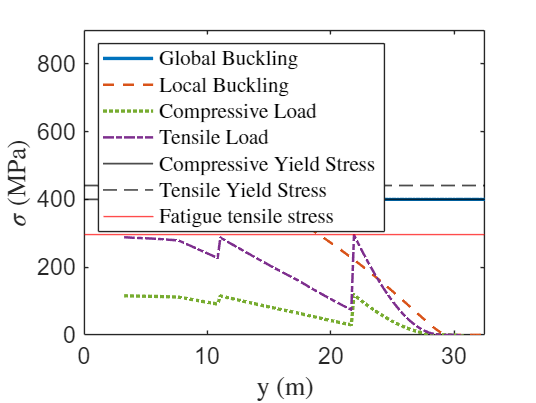

% Compressive Load: Dotted Green, Thick
plot(wing_opt.stripy(wingidx), -Nneg(wingidx)./wb.t_Lower(wingidx)*1e-6, ...
    'LineStyle', ':', 'Color', [0.4660, 0.6740, 0.1880], 'LineWidth', 2);
sigma_Lskin = -Nneg./wb.t_Lower;
% Tensile Load: Dash-Dot Purple, Medium
plot(wing_opt.stripy(wingidx), N(wingidx)./wb.t_Lower(wingidx)*1e-6, ...
    'LineStyle', '-.', 'Color', [0.4940, 0.1840, 0.5560], 'LineWidth', 1.5);
% Compressive Yield: Solid Black
yline(sigmaY_L*1e-6, 'LineStyle', '-', 'Color', 'k', 'LineWidth', 1);
% Tensile Yield: Dashed Black
yline(sigmaYT_L*1e-6, 'LineStyle', '--', 'Color', 'k', 'LineWidth', 1);
hold on
yline(sigma_max*1e-6,"r-")
legend("Global Buckling","Local Buckling","Compressive Load","Tensile Load",...
    "Compressive Yield Stress","Tensile Yield Stress","Fatigue tensile stress", "Interpreter","latex","Location","northwest");
xlabel("y (m)", "Interpreter", "latex");
ylabel("$\sigma$ (MPa)", "Interpreter", "latex");
xlim([0 wing_opt.s]);
ylim([0 900])
print(gcf, fullfile('images_new', 'LowerStressDiagram.png'), '-dpng', '-r300')

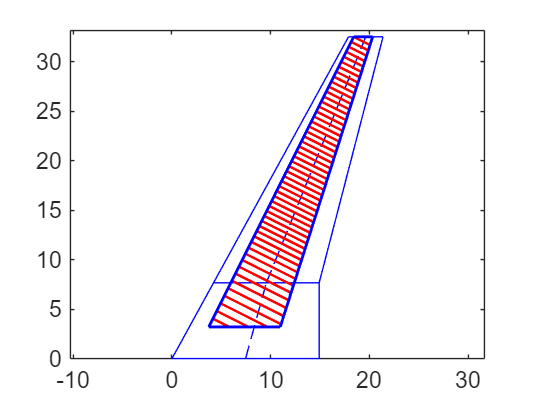



figure(6)
clf;
wing_opt.plotWing
hold on
wb.plotRibs(wing_opt)
hold on
wb.plotWingBox(wing_opt,D)
ylim([0 wing_opt.b/2*1.02])
axis equal
print(gcf, fullfile('images_new', 'Ribs.png'), '-dpng', '-r300')

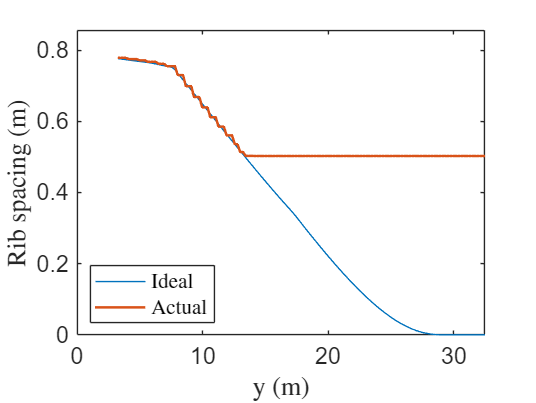


figure(4)
clf;
idealL = max(N.*E.*(sigmaY./wb.F).^(-2), 0);
plot(wing_opt.stripy(wingidx), max(idealL(wingidx),0),'Color', [0 0.4470 0.7410])
hold on
plot(wing_opt.stripy(wingidx), wb.L(wingidx),'LineWidth',1.5)
xlim([0, wing_opt.b/2])
ylim([0 max(wb.L*1.1)])
ylabel("Rib spacing (m)","Interpreter","latex")
xlabel("y (m)","Interpreter","latex")
legend("Ideal","Actual","Interpreter","latex","Location","southwest")
print(gcf, fullfile('images_new', 'RibSpacing.png'), '-dpng', '-r300');

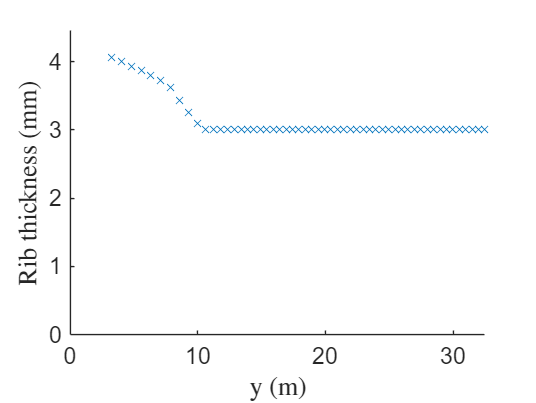


figure(5)
clf;
scatter(wb.yrib, wb.tr*1000,'x')
xlim([0, wing_opt.b/2])
ylim([0 max(wb.tr*1000*1.1)])
ylabel("Rib thickness (mm)","Interpreter","latex")
xlabel("y (m)","Interpreter","latex")
print(gcf, fullfile('images_new', 'RibThickness.png'), '-dpng', '-r300');

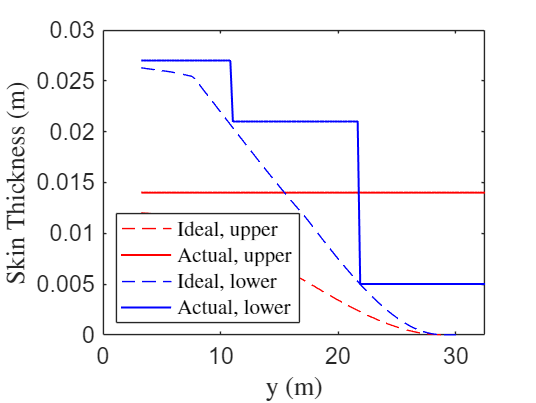


figure(6)
clf;
idealtUp = N./sigmaY;
idealtLow = N./sigma_max;

plot(ywing,idealtUp(wingidx),'r--')
hold on
plot(ywing, wb.t_Upper(wingidx),'r','LineWidth',1.2)
hold on
plot(ywing,idealtLow(wingidx),'b--')
hold on
plot(ywing,wb.t_Lower(wingidx),'b','LineWidth',1.2)
xlim([0, wing_opt.b/2])
ylim([0 0.03])
ylabel("Skin Thickness (m)","Interpreter","latex")
xlabel("y (m)","Interpreter","latex")
legend("Ideal, upper","Actual, upper","Ideal, lower","Actual, lower","Interpreter","latex","Location","southwest")
print(gcf, fullfile('images_new', 'SkinThickness.png'), '-dpng', '-r300');

## **3. Spar buckling analysis(get spar thickness)**

**Web is fixed at top/bottom, SS at sides (web stringers)**

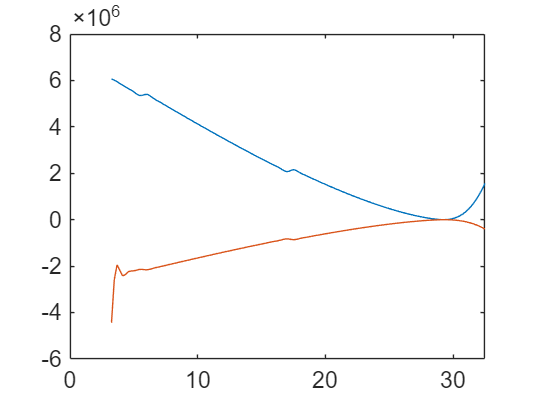

%[t_FS, t_RS] = Sparfun(wb, wing_opt,material,V,T,wbStress)

%for maximum buckling coefficient, let a = h
wb.a = wb.b2_c.*wing_opt.cn;
Ks = 8.1;
E = Al7068.E;

%Use same As/bt and ts/t
%z stringer
figure(1)
clf;
plot(wing_opt.stripy(wingidx), S(wingidx))
hold on
plot(wing_opt.stripy(wingidx), Sneg(wingidx))
xlim([0 wing_opt.b/2])

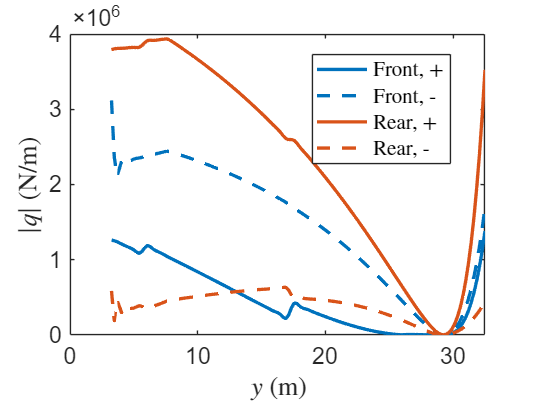


Awb = wb.c_c.*wb.b2_c.*wing_opt.cn.*wing_opt.cn;
hwb = wb.b2_c.*wing_opt.cn;

q = @(S,T,h,A) S./(2*h) + T./(2*A);

qFpos = q(-S,tau,hwb,Awb);
qFneg = q(-Sneg,tau,hwb,Awb);
qRpos = q(-S,-tau,hwb,Awb);
qRneg = q(-Sneg,-tau,hwb,Awb);

figure(2);
clf;

% Define line styles/colors for clarity
front_color = [0, 0.4470, 0.7410];  % Blue for front
rear_color = [0.8500, 0.3250, 0.0980];  % Red for rear
linewidth = 2;  % Thicker lines for visibility

% Plot front (+/-)
plot(wing_opt.stripy(wingidx), abs(qFpos(wingidx)), ...
    'Color', front_color, 'LineStyle', '-', 'LineWidth', linewidth);
hold on;
plot(wing_opt.stripy(wingidx), abs(qFneg(wingidx)), ...
    'Color', front_color, 'LineStyle', '--', 'LineWidth', linewidth);

% Plot rear (+/-)
plot(wing_opt.stripy(wingidx), abs(qRpos(wingidx)), ...
    'Color', rear_color, 'LineStyle', '-', 'LineWidth', linewidth);
plot(wing_opt.stripy(wingidx), abs(qRneg(wingidx)), ...
    'Color', rear_color, 'LineStyle', '--', 'LineWidth', linewidth);

% Formatting
legend("Front, +", "Front, -", "Rear, +", "Rear, -", ...
    'Interpreter', 'latex', 'Location', 'best');
ylabel("$\left| q \right|$ (N/m)", "Interpreter", "latex");
xlabel("$y$ (m)", "Interpreter", "latex");
xlim([0, wing_opt.b/2]);

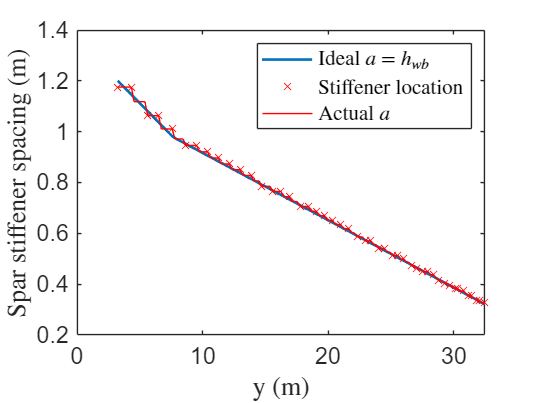

[y_spar_s, N_spar_s] = createRibLocationsFromL(wb.b2_c.*wing_opt.cn, wing_opt, D);
y_wing = wing_opt.stripy;
yrib   = y_spar_s;

% Sort yrib if not already sorted
yrib = sort(yrib);

% Pre-allocate L
L = zeros(size(y_wing));

for i = 1:length(y_wing)
    y_i = y_wing(i);

    % 1) Check if y_i is within [-D/2, D/2]
    if (y_i >= -D/2) && (y_i <= D/2)
        % If in the fuselage region, set L to NaN
        L(i) = NaN;
    else
        % 2) Otherwise, find the adjacent ribs
        k = find(yrib <= y_i, 1, 'last');

        if isempty(k)
            % y_i < yrib(1)
            L(i) = yrib(2) - yrib(1);
        elseif k == length(yrib)
            % y_i >= yrib(end)
            L(i) = yrib(end) - yrib(end-1);
        else
            % y_i lies between yrib(k) and yrib(k+1)
            L(i) = yrib(k+1) - yrib(k);
        end
    end
end

a = L;
wb.a = L;

% Initialize an array to store the indices
sparidx = NaN(size(y_spar_s)); % Use NaN for excluded points

% Loop through each point in y_spar_s
for i = 1:length(y_spar_s)
    % Find the index of the closest point in wing_opt.stripy
    [~, idx] = min(abs(wing_opt.stripy - y_spar_s(i)));
    
    % Check if the corresponding wing_opt.stripy value is within the desired range
    if abs(wing_opt.stripy(idx)) >= D/2
        sparidx(i) = idx; % Store the index if the condition is satisfied
    end
    % Otherwise, sparidx(i) remains NaN (excluded)
end



figure(3)
clf;
plot(wing_opt.stripy(wingidx), wb.b2_c.*wing_opt.cn(wingidx),'LineWidth',1.6)
hold on
scatter(wing_opt.stripy(sparidx), wb.a(sparidx),'x','r')
hold on
plot(wing_opt.stripy(wingidx), wb.a(wingidx),'r')
legend("Ideal $a$ = $h_{wb}$","Stiffener location","Actual $a$", "Interpreter", "latex")
xlabel("y (m)", "Interpreter", "latex")
ylabel("Spar stiffener spacing (m)", "Interpreter", "latex")
xlim([0 wing_opt.b/2])
print(gcf, fullfile('images_new', 'aspar.png'), '-dpng', '-r300');

wb.y_sparS = wing_opt.stripy(sparidx);

q_FS = abs(qFneg);
q_RS = abs(qRpos);

t_FS = (q_FS .* b2 ./ Ks ./ E).^(1/3);%thickness front spar
t_RS = (q_RS .* b2 ./ Ks ./ E).^(1/3);%thickness

tFd = [0.019 0.016 0.011]

tFd =     0.0190    0.0160    0.0110


tRd = [0.02 0.018 0.013]

tRd =     0.0200    0.0180    0.0130



wb.tF = thicknessDoubler(flip(t_FS),wing_opt.stripy,D)

wb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: [0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 … ] (1×301 double)
             tR: []
            c_c: 0.5500
           b1_c: [0.1100 0.1081 0.1062 0.1044 0.1027 0.1010 0.0994 0.0978 

wb.tR = thicknessDoubler(flip(t_RS),wing_opt.stripy,D)

wb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: [0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 … ] (1×301 double)
             tR: [0.0130 0.0130 0.0130 0.0130 0.0130 0.0130 0.0130 0.0130 0.0130 0.0130 0.0130 0.0130 0.0130 0.0130 0.

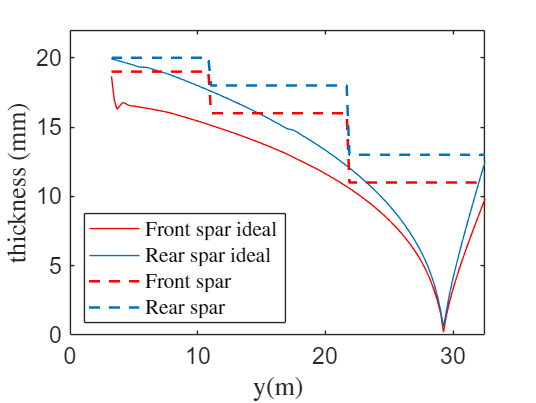



figure(4)
clf;
plot(wing_opt.stripy(wingidx),t_FS(wingidx)*1000,'r')
hold on
plot(wing_opt.stripy(wingidx),t_RS(wingidx)*1000,'Color', [0 0.4470 0.7410])
hold on
plot(wing_opt.stripy(wingidx),wb.tF(wingidx)*1000,'r--','LineWidth',1.5)
hold on
plot(wing_opt.stripy(wingidx),wb.tR(wingidx)*1000, 'Color', [0 0.4470 0.7410], 'LineStyle', '--', 'LineWidth', 1.5)
legend("Front spar ideal","Rear spar ideal", "Front spar","Rear spar","Location","SouthWest","Interpreter", "latex")
xlim([0, wing_opt.b/2]);
xlabel("y(m)", "Interpreter", "latex")
ylabel("thickness (mm)", "Interpreter", "latex")
ylim([0 0.022*1000])
print(gcf, fullfile('images_new', 'tspar.png'), '-dpng', '-r300');


t_sFS = ts_t * wb.tF;
t_sRS = ts_t * wb.tR;

%hs = (1.672 a t)/(1.6 ts)
h_sFS = (As_bt.*wb.a.*wb.tF)./(1.6.*t_sFS)

h_sFS =     0.0619    0.0619    0.0634    0.0634    0.0652    0.0669    0.0669    0.0687    0.0707    0.0707    0.0725    0.0725    0.0744    0.0744    0.0764    0.0764    0.0785    0.0785    0.0807    0.0828    0.0828    0.0851    0.0851    0.0851    0.0874    0.0874    0.0897    0.0897    0.0921    0.0921    0.0946    0.0946    0.0972    0.0972    0.0972    0.0998    0.0998    0.1025    0.1025    0.1025    0.1053    0.1053    0.1081    0.1081    0.1081    0.1110    0.1110    0.1110    0.1140    0.1140


h_sRS = (As_bt.*wb.a.*wb.tR)./(1.6.*t_sRS)

h_sRS =     0.0619    0.0619    0.0634    0.0634    0.0652    0.0669    0.0669    0.0687    0.0707    0.0707    0.0725    0.0725    0.0744    0.0744    0.0764    0.0764    0.0785    0.0785    0.0807    0.0828    0.0828    0.0851    0.0851    0.0851    0.0874    0.0874    0.0897    0.0897    0.0921    0.0921    0.0946    0.0946    0.0972    0.0972    0.0972    0.0998    0.0998    0.1025    0.1025    0.1025    0.1053    0.1053    0.1081    0.1081    0.1081    0.1110    0.1110    0.1110    0.1140    0.1140


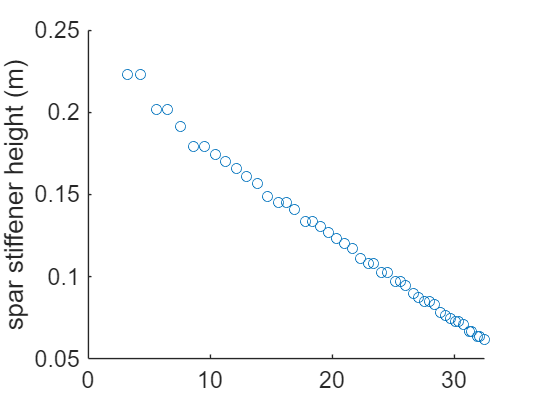

figure(5)
clf;
scatter(wing_opt.stripy(sparidx), h_sFS(sparidx))
ylabel("spar stiffener height (m)")
xlim([0 wing_opt.b/2])
print(gcf, fullfile('images_new', 'hss.png'), '-dpng', '-r300');


% %Verify interactive buckling in spar
% %check front spar
% tau_cr = 8.1*E.*(wb.tF./wb.a).^2;
% tau_cr_tresca = 125*1e6;
% tau_0 = qFneg./wb.tF;
% 
% Asbt_spar = t_sFS.*h_sFS*1.6./(wb.a.*t_sFS);
% ts_t_spar = 1.076;
% 
% R_c = interpsr_s0(Asbt_spar,ts_t_spar);
% R_s = tau_cr_tresca/tau_0;

IxFS = 1/12*wb.tF.*(wb.b2_c.*wing_opt.cn).^3;
sigma_cFS = M.*wb.b2_c.*wing_opt.cn/2./IxFS

sigma_cFS = 1.0e+10 *

   -0.1617   -0.1240   -0.0932   -0.0686   -0.0490   -0.0339   -0.0224   -0.0139   -0.0079   -0.0039   -0.0015   -0.0002    0.0003    0.0003    0.0001   -0.0000    0.0001    0.0008    0.0021    0.0042    0.0072    0.0112    0.0162    0.0221    0.0291    0.0371    0.0462    0.0562    0.0672    0.0792    0.0921    0.1059    0.1206    0.1363    0.1527    0.1700    0.1880    0.2069    0.2264    0.2467    0.2677    0.2893    0.3116    0.3345    0.3580    0.3820    0.4066    0.4317    0.4573    0.4834



IxRS = 1/12*wb.tR.*(wb.b2_c.*wing_opt.cn).^3;
sigma_cRS = M.*wb.b2_c.*wing_opt.cn/2./IxRS

sigma_cRS = 1.0e+10 *

   -0.1368   -0.1049   -0.0789   -0.0580   -0.0415   -0.0286   -0.0189   -0.0118   -0.0067   -0.0033   -0.0013   -0.0002    0.0002    0.0002    0.0001   -0.0000    0.0001    0.0007    0.0018    0.0036    0.0061    0.0095    0.0137    0.0187    0.0246    0.0314    0.0391    0.0475    0.0568    0.0670    0.0779    0.0896    0.1021    0.1153    0.1292    0.1438    0.1591    0.1750    0.1916    0.2088    0.2265    0.2448    0.2637    0.2830    0.3029    0.3232    0.3440    0.3653    0.3870    0.4090


## 4. Dcell

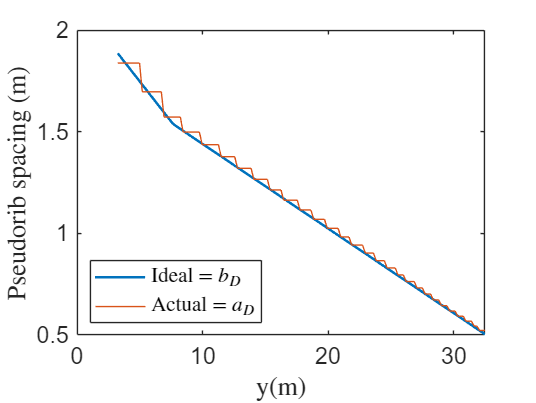

sigmaY = Al7068.sigma_y_tensile;
sigma_yield_tens = Al7068.sigma_y_tensile; % [Pa] From your material data
E = Al7068.E;                              % [Pa] Young’s modulus
b_D = pi * wb.R_c .* wing_opt.cn;          % [m] D-cell circumference (already computed)
[yprib, Nprib] = createRibLocationsFromL(b_D, wing_opt, D);

y_wing = wing_opt.stripy;
yrib   = yprib;

% Sort yrib if not already sorted
yrib = sort(yrib);

% Pre-allocate L
L = zeros(size(y_wing));

for i = 1:length(y_wing)
    y_i = y_wing(i);

    % 1) Check if y_i is within [-D/2, D/2]
    if (y_i >= -D/2) && (y_i <= D/2)
        % If in the fuselage region, set L to NaN
        L(i) = NaN;
    else
        % 2) Otherwise, find the adjacent ribs
        k = find(yrib <= y_i, 1, 'last');

        if isempty(k)
            % y_i < yrib(1)
            L(i) = yrib(2) - yrib(1);
        elseif k == length(yrib)
            % y_i >= yrib(end)
            L(i) = yrib(end) - yrib(end-1);
        else
            % y_i lies between yrib(k) and yrib(k+1)
            L(i) = yrib(k+1) - yrib(k);
        end
    end
end

wb.a_D = L;

figure(1)
clf;
plot(wing_opt.stripy(wingidx),b_D(wingidx),'LineWidth',1.5)
hold on
plot(wing_opt.stripy(wingidx),wb.a_D(wingidx))
legend("Ideal = $b_D$","Actual = $a_D$","Location","SouthWest","Interpreter", "latex")
xlim([0, wing_opt.b/2]);
xlabel("y(m)", "Interpreter", "latex")
ylabel("Pseudorib spacing (m)", "Interpreter", "latex")
print(gcf, fullfile('images_new', 'pseudorib.png'), '-dpng', '-r300');


wb.Nprib =58; 

a_D = wb.a_D;
b_D = pi*wb.R_c.*wing_opt.cn;
R = wb.R_c.*wing_opt.cn;
taumax = sigmaY/2;

%initial guess
t1 = 20e-3*ones(size(wing_opt.stripy));
t2 = 20e-3*ones(size(wing_opt.stripy));
converged = false

converged = logical
   0


iter = 0 

iter = 0

maxiter = 6

maxiter = 6

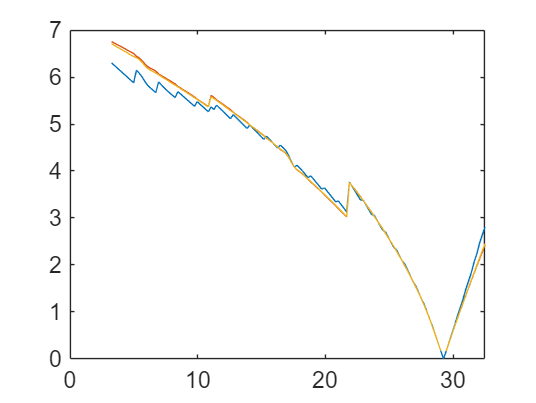

    0.0063

    0.0068



Converged


    0.0067



figure
while converged == false && iter < maxiter
    q_D = [];
    t1 = real(t2);
    for j =1:length(wingidx)
        i = wingidx(j);
        [~, q_D(i)] = shearFlow(wing_opt.cn(i), wb, tau(i), wb.t_Upper(i), wb.t_Lower(i), wb.tF(i), wb.tR(i), t1(i));
        %shear stress = q / t = buckling shear stress
    end
    b_RT = b_D./sqrt(R.*t1);
    b_RT = b_RT(wingidx);
    Ks = [];
    for j =1:length(wingidx)
        i = wingidx(j);
        Ks(i) = interpKspolyfit(R(i),t1(i),a_D(i),b_D(i));
    end
    %t2 = q_D./(Ks.*E.*t1.^2./b_D.^2);
    t2 = b_D.*sqrt((q_D./t1)./(Ks.*E));
    if abs(max(t2) - max(t1)) < 1e-4
        converged = true;
        disp("Converged")
    end
    plot(wing_opt.stripy(wingidx),t2(wingidx)*1000)
    hold on
    iter = iter + 1;
    disp(max(t2))
    %converged = true
end

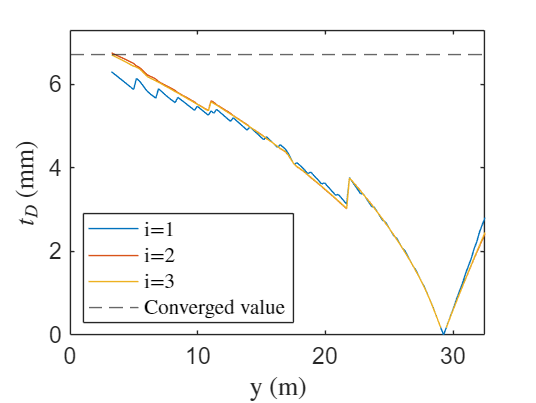

hold on
yline(max(t2)*1000,'--')
xlabel("y (m)","Interpreter","latex")
ylabel("$t_D$ (mm)","Interpreter","latex")
legend("i=1","i=2","i=3","Converged value","Interpreter","Latex","Location","SouthWest")
wb.tD = max(t2);
wb.tr_D = 3e-3;
ylim([0 7.3])

%print(gcf, fullfile('images_new', 'tD.png'), '-dpng', '-r300');

Interactive Buckling

Verify for upper and lower skin, front and rear spar

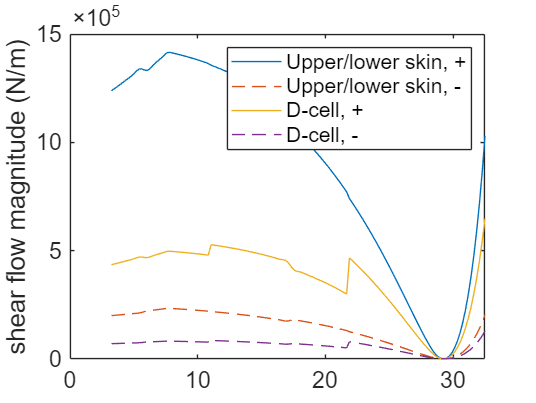

qF = -S./(2.*wb.b2_c.*wing_opt.cn);
qFneg = -Sneg./(2.*wb.b2_c.*wing_opt.cn);



q_wb = [];
q_D = [];
q_wbneg = [];
q_Dneg = [];
for j = 1:length(wingidx)
    i = wingidx(j);
    [q_wb(i), q_D(i)] = shearFlow(wing_opt.cn(i), wb, tau(i), wb.t_Upper(i), wb.t_Lower(i), wb.tF(i), wb.tR(i), wb.tD);
    [q_wbneg(i), q_Dneg(i)] = shearFlow(wing_opt.cn(i), wb, tauneg(i), wb.t_Upper(i), wb.t_Lower(i), wb.tF(i), wb.tR(i), wb.tD);
end



figure(1)
clf;
plot(wing_opt.stripy(wingidx),q_wb(wingidx))
hold on
plot(wing_opt.stripy(wingidx),abs(q_wbneg(wingidx)),'--')
hold on
plot(wing_opt.stripy(wingidx),abs(q_D(wingidx)))
hold on
plot(wing_opt.stripy(wingidx),abs(q_Dneg(wingidx)),'--')
legend("Upper/lower skin, +","Upper/lower skin, -","D-cell, +","D-cell, -")
ylabel("shear flow magnitude (N/m)")
xlim([0 wing_opt.b/2])



%in upper skin, q_wb
RcU = sigma_Uskin./sigmacr_Uskin

RcU =    0.0000 + 0.1737i   0.0000 + 0.1521i   0.0000 + 0.1319i   0.0000 + 0.1131i   0.0000 + 0.0957i   0.0000 + 0.0795i   0.0000 + 0.0646i   0.0000 + 0.0509i   0.0000 + 0.0385i   0.0000 + 0.0271i   0.0000 + 0.0168i   0.0000 + 0.0065i   0.0071 + 0.0000i   0.0073 + 0.0000i   0.0045 + 0.0000i   0.0000 + 0.0014i   0.0053 + 0.0000i   0.0121 + 0.0000i   0.0197 + 0.0000i   0.0280 + 0.0000i   0.0367 + 0.0000i   0.0457 + 0.0000i   0.0549 + 0.0000i   0.0643 + 0.0000i   0.0737 + 0.0000i   0.0833 + 0.0000i   0.0928 + 0.0000i   0.1024 + 0.0000i   0.1120 + 0.0000i   0.1216 + 0.0000i   0.1311 + 0.0000i   0.1406 + 0.0000i   0.1501 + 0.0000i   0.1595 + 0.0000i   0.1688 + 0.0000i   0.1781 + 0.0000i   0.1874 + 0.0000i   0.1965 + 0.0000i   0.2056 + 0.0000i   0.2146 + 0.0000i   0.2235 + 0.0000i   0.2324 + 0.0000i   0.2412 + 0.0000i   0.2499 + 0.0000i   0.2585 + 0.0000i   0.2670 + 0.0000i   0.2755 + 0.0000i   0.2839 + 0.0000i   0.2922 + 0.0000i   0.3004 + 0.0000i


RsU = q_wb./wb.t_Upper./(sigmaYT./2)

RsU =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%in lower skin, q_wb
RcL = sigma_Lskin./sigmacr_Lskin

RcL =    0.0000 + 0.3576i   0.0000 + 0.3153i   0.0000 + 0.2757i   0.0000 + 0.2388i   0.0000 + 0.2045i   0.0000 + 0.1728i   0.0000 + 0.1435i   0.0000 + 0.1167i   0.0000 + 0.0924i   0.0000 + 0.0705i   0.0000 + 0.0510i   0.0000 + 0.0342i   0.0000 + 0.0202i   0.0000 + 0.0094i   0.0000 + 0.0032i   0.0027 + 0.0000i   0.0112 + 0.0000i   0.0221 + 0.0000i   0.0350 + 0.0000i   0.0495 + 0.0000i   0.0650 + 0.0000i   0.0809 + 0.0000i   0.0973 + 0.0000i   0.1138 + 0.0000i   0.1306 + 0.0000i   0.1474 + 0.0000i   0.1644 + 0.0000i   0.1813 + 0.0000i   0.1983 + 0.0000i   0.2153 + 0.0000i   0.2322 + 0.0000i   0.2490 + 0.0000i   0.2657 + 0.0000i   0.2824 + 0.0000i   0.2990 + 0.0000i   0.3154 + 0.0000i   0.3318 + 0.0000i   0.3480 + 0.0000i   0.3641 + 0.0000i   0.3800 + 0.0000i   0.3959 + 0.0000i   0.4116 + 0.0000i   0.4271 + 0.0000i   0.4425 + 0.0000i   0.4578 + 0.0000i   0.4729 + 0.0000i   0.4879 + 0.0000i   0.5027 + 0.0000i   0.5174 + 0.0000i   0.5319 + 0.0000i


RsL = q_wb./wb.t_Lower./(sigmaYT_L./2)

RsL =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



xspace = linspace(0,1,100);
figure(2)
clf;
scatter(RcU(wingidx),RsU(wingidx),'x')

hold on
scatter(RcL(wingidx),RsL(wingidx),'.')

hold on
plot(xspace, sqrt(0.99-xspace),'k','LineWidth',1.5)

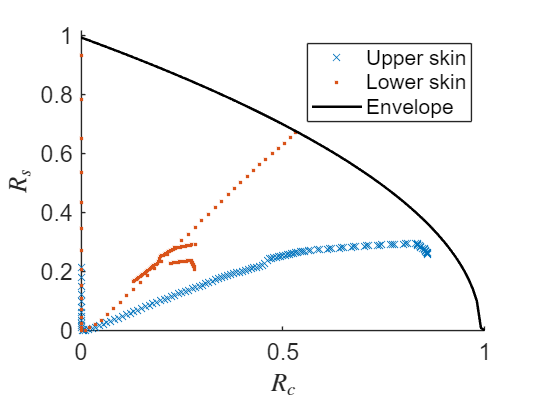

xlabel("$R_c$","Interpreter","latex")
ylabel("$R_s$","Interpreter","latex")
legend("Upper skin","Lower skin","Envelope")
ylim([0 1.02])
print(gcf, fullfile('images_new', 'Interactive Buckling.png'), '-dpng', '-r300');


%find index that RcU + RsU^2 > 0.99
idx = find(RcU + RsU.^2 > 0.99);
wing_opt.stripy(idx)


ans =

  1×0 empty double row vector



[Mass_Lskin,M_Lskin,M_Lskin_stringer,thiswb.b1_c_Lower] = LskinMass(rho_Lskin, wing_opt, thiswb, wingidx)

Mass_Lskin = 3.9029e+04

M_Lskin = 1.3621e+04

M_Lskin_stringer = 2.5408e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1108 0.1088 0.1069 0.1051 0.1033 0.1016 0.1000 0.0984 0.0969 0.0954 0.0939 0.0925 0.0911 0.0898 0.0885 0.0873 0.0861 0.0849 0.0837 0.0826 0.0815 0.0805 0.0794 0.0784 0.0774 0.0765 0.0755 0.0746 0.0737 0.0729 0.0720 … ] (1×301 double)
     b1_c_Lower: [0.0503 0.0495 0.0486 0.0478 0.04

[Mass_Uskin,M_Uskin,M_Uskin_stringer,thiswb.b1_c] = UskinMass(rho_Uskin, wing_opt, thiswb, wingidx)

Mass_Uskin = 2.9626e+04

M_Uskin = 1.0042e+04

M_Uskin_stringer = 1.9584e+04

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 0.0140 … ] (1×301 double)
        t_Lower: [0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 0.0050 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.1108 0.1088 0.1069 0.1051 0.1033 0.1016 0.1000 0.0984 0.0969 0.0954 0.0939 0.0925 0.0911 0.0898 0.0885 0.0873 0.0861 0.0849 0.0837 0.0826 0.0815 0.0805 0.0794 0.0784 0.0774 0.0765 0.0755 0.0746 0.0737 0.0729 0.0720 … ] (1×301 double)
     b1_c_Lower: [0.0503 0.0495 0.0486 0.0478 0.04



M_Uskin

M_Uskin = 1.0042e+04

M_Uskin_stringer

M_Uskin_stringer = 1.9584e+04

Mass_Uskin

Mass_Uskin = 2.9626e+04


M_Lskin

M_Lskin = 1.3621e+04

M_Lskin_stringer

M_Lskin_stringer = 2.5408e+04

Mass_Lskin

Mass_Lskin = 3.9029e+04


Mrib = ribMass(thiswb, wing_opt, rho_r)

Mrib = 2.5340e+03


%4. front spar
ywing = wing_opt.stripy(wingidx);
tFwing = wb.tF(wingidx);
hF = [];
for i = 1:length(ywing)
    hF(i) = wb.b2_c.*wing_opt.c_at_y(ywing(i));
end
V_FS = trapz(ywing, hF.*tFwing)*2;
As_FS = h_sFS(wingidx).*t_sFS(wingidx).*(1 + 0.3*2);
V_FS_skin = V_FS;
V_FS_stiffeners =  trapz(ywing,As_FS)*2;
V_FS = V_FS  +V_FS_stiffeners;
MFS_stiffeners = V_FS_stiffeners*Al7068.rho;
MFS = V_FS*Al7068.rho

MFS = 2.5620e+03

MFS_total = V_FS*Al7068.rho

MFS_total = 2.5620e+03



%5. rear spar
tRwing = wb.tR(wingidx);
V_RS = trapz(ywing, hF.*tRwing);
As_RS = h_sRS(wingidx).*t_sRS(wingidx).*(1 + 0.3*2);
V_RS_skin = V_RS;
V_RS_stiffeners =  trapz(ywing,As_RS)*2;
V_RS = V_RS  +V_RS_stiffeners;
MRS_stiffeners = V_RS_stiffeners*Al7068.rho

MRS_stiffeners = 726.6104

MRS = V_RS*Al7068.rho

MRS = 1.7748e+03

MRS_total = V_RS*Al7068.rho

MRS_total = 1.7748e+03


%6. D cell
V_D = trapz(ywing, wb.tD.*pi.*wb.R_c.*wing_opt.cn(wingidx))*2;
V_Dr = sum(wb.tr_D.*1/2.*pi*(wb.R_c.*wing_opt.cn(wingidx)).^2)*2;
V_D_total = V_D + V_Dr;
MD = V_D*Al7068.rho

MD = 1.2571e+03

MD_pr = V_Dr*Al7068.rho

MD_pr = 520.3948

MD_total = V_D_total*Al7068.rho

MD_total = 1.7775e+03


total = Mass_Uskin + Mass_Lskin + Mrib + MFS_total + MRS_total + MD_total

total = 7.7303e+04

M_Uskin.*Al7068.price

ans = 3.6253e+04

M_Uskin_stringer.*Al7068.price

ans = 7.0697e+04



M_Lskin.*Al2024.price

ans = 2.5607e+04

M_Lskin_stringer.*Al2024.price

ans = 4.7767e+04


Mrib.*Al7068.price

ans = 9.1476e+03


MFS_stiffeners.*Al7068.price

ans = 2.3806e+03

MFS.*Al7068.price

ans = 9.2488e+03


MRS_stiffeners.*Al7068.price

ans = 2.6231e+03

MRS.*Al7068.price

ans = 6.4069e+03


MD.*Al7068.price

ans = 4.5380e+03

MD_pr.*Al7068.price

ans = 1.8786e+03